% SETUP
clear all
clc
addpath('./Realization')
addpath('./MPC')

## Problem 2

### 2.1 Deterministic Nonlinear Model

Dynamics: Can be found in ModifiedFourTankSystem.m 

Measurements: Can be found in FourTankSystemSensors.m 

Outputs: Can be found in FourTankSystemOutput.m 

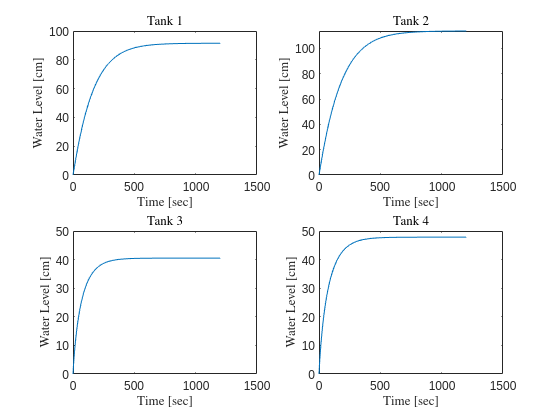

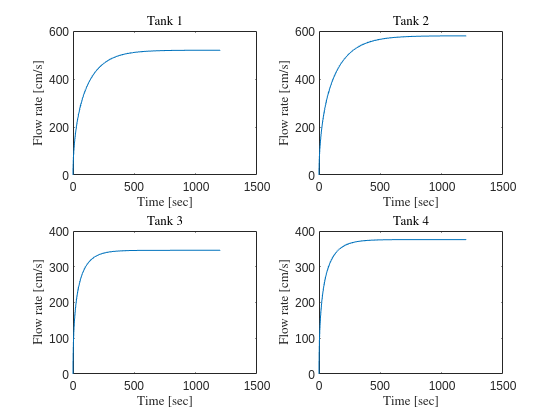

% get parameters
p = GetParameters();

% flow rate steady state
F = [300, 300, 250, 250];

% simulate
[T, H, Qout] = simulateDeterministic(F, p);

plotting(T, H, Qout, "Deterministic Nonlinear Model")

### 2.2 Stochastic Nonlinear Model

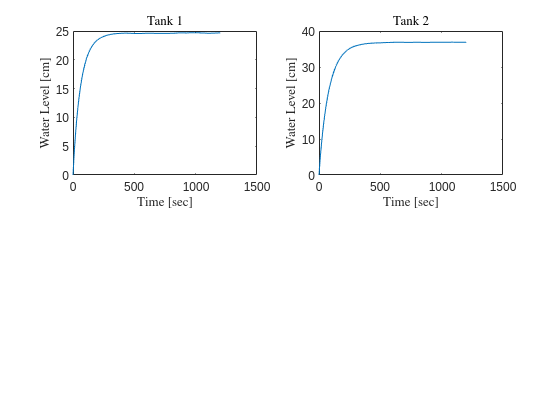

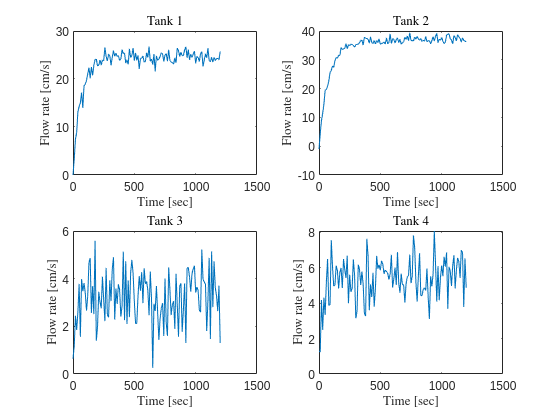

t0 = 0.0;
tfin = 20*60;
Ts = 10;
t = [t0:Ts:tfin];     % time vector
N = length(t);

F1 = 300;
F2 = 300;
u = [repmat(F1,1,N); repmat(F2,1,N)];   % control 

d = [randn(1,N); randn(1,N)];   % disturbances F3, F4
r = [13, 10, 4, 4];
parameters = GetParameters();

P = eye(1);
Pq = chol(P,'lower');

% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);

nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);


s = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
step_size = 0.01;
x(:,1) = [0;0;0;0];

for k = 1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function WITH noise 
    s(:,k) = FourTankSystemOutput(x(:,k),parameters);
    % Output function
    disturbance_without_noise = d(:,k); % +w(:,k);
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k):step_size:t(k+1)],x(:,k),[], ...
        u(:,k),disturbance_without_noise,parameters);
    x(:,k+1) = Xk(end,:)';
    % T = [T; Tk];
    X = [X; Xk];
end

k = N;
y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function
s(:,k) = FourTankSystemOutput(x(:,k),parameters);        % Output function

plotting(t, s', y', "Stochastic Nonlinear Model");

### 2.3 Stochastic Nonlinear Model (SDE)

Model sisturbance as Brownian motion with some variance

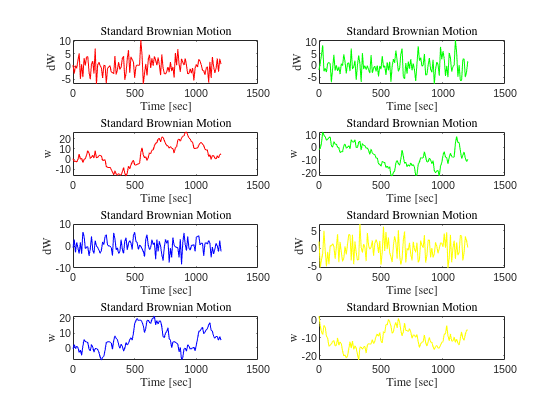

t0 = 0.0;
tfin = 20*60;
Ts = 10;
t = [t0:Ts:tfin];     % time vector
N = length(t);

sz = 4;
su = 2;

% Realization of Ns Standard Brownian Motions
Ns = 4;            % Number of realizations
seed = 100;         % Seed for reproducibility
rng(seed);
dV = sqrt(Ts)*randn(Ns,N);
v = cumsum(dV,2);

figure()
title('Standard Brownian Motion','interpreter','latex')

subplot(4,2,1)
plot(t,dV(1, :), 'color', 'r')
xlabel('Time [sec]','interpreter','latex')
ylabel('dW','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,3)
plot(t,v(1,:), 'color', 'r')
xlabel('Time [sec]','interpreter','latex')
ylabel('w','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,2)
plot(t,dV(2, :), 'color', 'g')
xlabel('Time [sec]','interpreter','latex')
ylabel('dW','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,4)
plot(t,v(2, :), 'color', 'g')
xlabel('Time [sec]','interpreter','latex')
ylabel('w','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,5)
plot(t,dV(3, :), 'color', 'b')
xlabel('Time [sec]','interpreter','latex')
ylabel('dW','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,7)
plot(t,v(3,:), 'color', 'b')
xlabel('Time [sec]','interpreter','latex')

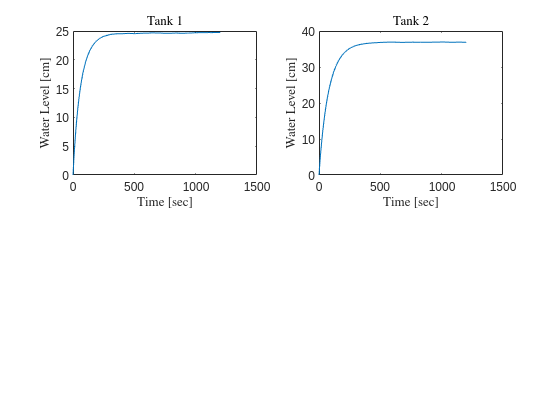

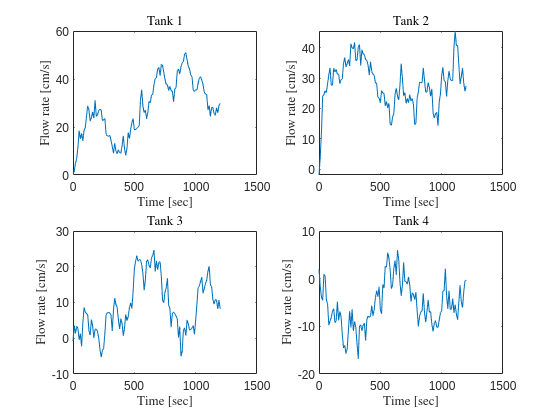

ylabel('w','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,6)
plot(t,dV(4, :), 'color', 'y')
xlabel('Time [sec]','interpreter','latex')
ylabel('dW','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,8)
plot(t,v(4, :), 'color', 'y')
xlabel('Time [sec]','interpreter','latex')
ylabel('w','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')


F1 = 300;
F2 = 300;
u = [repmat(F1,1,N); repmat(F2,1,N)];   % control 

d = [randn(1,N); randn(1,N)];   % disturbances F3, F4
r = [13, 10, 4, 4];
parameters = GetParameters();

P = eye(1);
Pq = chol(P,'lower');
x0 = Pq*randn(4, 1);

nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);


s = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
step_size = 0.01;
x(:,1) = [0;0;0;0];

for k = 1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function WITH noise 
    s(:,k) = FourTankSystemOutput(x(:,k),parameters);
    % Output function
    disturbance_without_noise = d(:,k); % +w(:,k);
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k):step_size:t(k+1)],x(:,k),[], ...
        u(:,k),disturbance_without_noise,parameters);
    x(:,k+1) = Xk(end,:)';
    % T = [T; Tk];
    X = [X; Xk];
end

k = N;
y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function
s(:,k) = FourTankSystemOutput(x(:,k),parameters);        % Output function

plotting(t, s', y', "Stochastic Nonlinear Model");

## Problem 3 Nonlinear Simulation - Step Responses

### 3.1 Simulate the step responses for 10%, 25% and 50% steps in the manipulated variables. Do this for the deterministic model

% get parameters
p = GetParameters();

% flow rate steady state
F = [300, 300, 250, 250];

%% get steady state of system 
[xs, hs] = computeSteadyState(p, F)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 1.0e+04 *

    3.4787
    4.3277
    1.5401
    1.8188


hs =    91.5118
  113.8482
   40.5156
   47.8460



%% compute step response x% steady state 
F_d1 = F * 1.1;    % 10%
F_d2 = F * 1.25;   % 25%
F_d3 = F * 1.5;    % 50%

[T1, H1, Qout1] = simulateDeterministic(F_d1, p);
[xs1, hs1] = computeSteadyState(p, F_d1);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


[T2, H2, Qout2] = simulateDeterministic(F_d2, p);
[xs2, hs2] = computeSteadyState(p, F_d2);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


[T3, H3, Qout3] = simulateDeterministic(F_d3, p);
[xs3, hs3] = computeSteadyState(p, F_d3);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


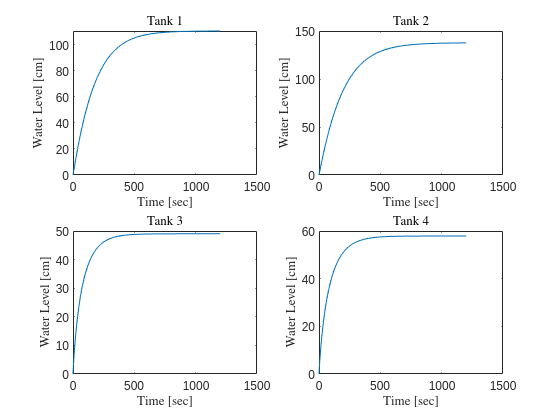

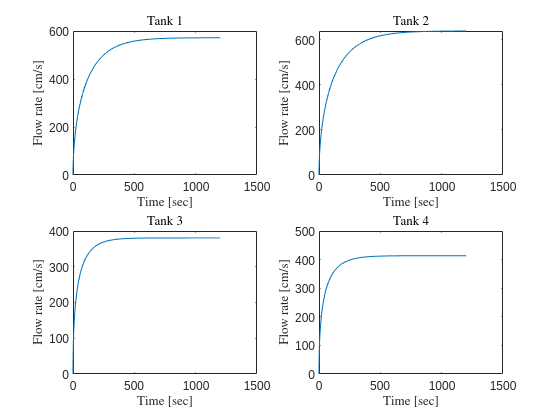


plotting(T1, H1, Qout1, "10%")

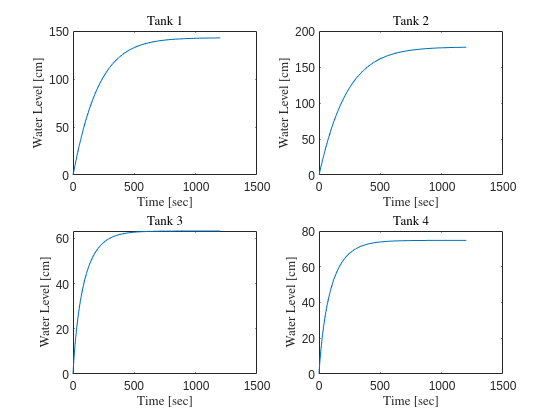

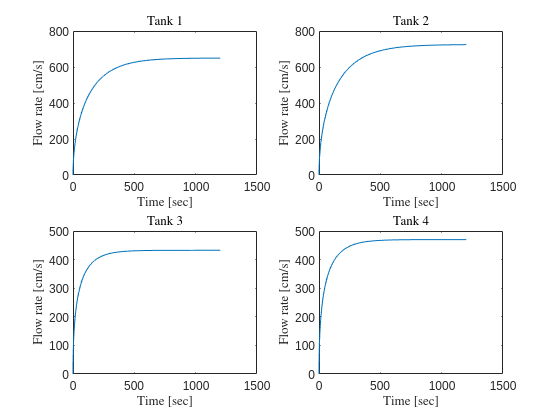

plotting(T2, H2, Qout2, "25%")

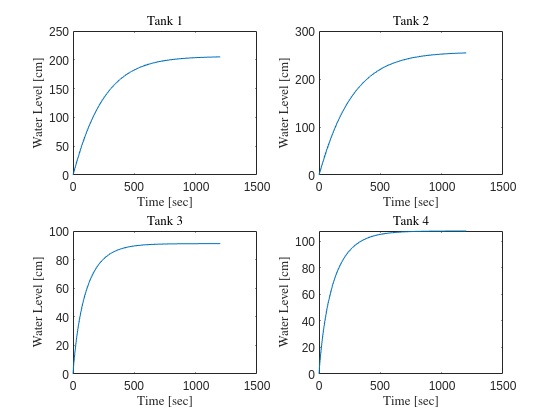

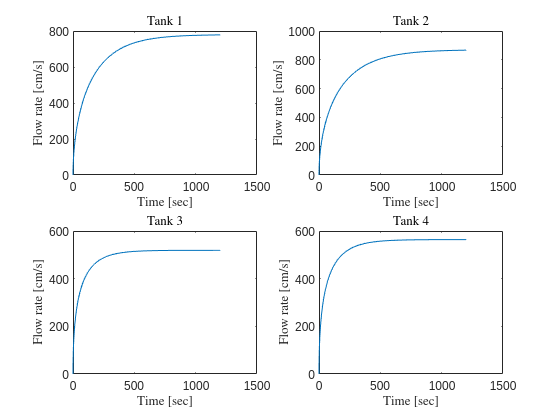

plotting(T3, H3, Qout3, "50%")

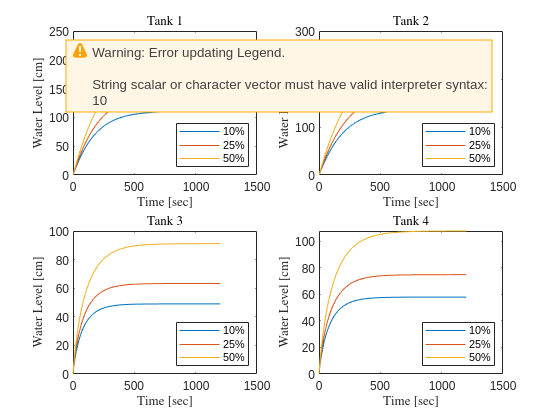


figure()

subplot(2,2,1)
plot(T1,H1(:, 1))
hold on 
plot(T2,H2(:, 1))
hold on
plot(T3,H3(:, 1))
hold off
legend('10%', '25%', '50%', 'interpreter', 'latex','Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,2)
plot(T1,H1(:, 2))
hold on 
plot(T2,H2(:, 2))
hold on
plot(T3,H3(:, 2))
hold off
legend('10%', '25%', '50%', 'interpreter', 'latex','Location','southeast')
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,3)
plot(T1,H1(:, 3))
hold on 
plot(T2,H2(:, 3))
hold on
plot(T3,H3(:, 3))
hold off
legend('10%', '25%', '50%', 'interpreter', 'latex','Location','southeast')
title('Tank 3','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,4)
plot(T1,H1(:, 4))
hold on 
plot(T2,H2(:, 4))
hold on
plot(T3,H3(:, 4))
hold off
legend('10%', '25%', '50%' ,'interpreter', 'latex','Location','southeast')
title('Tank 4','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

### 3.2 Simulate the step responses for 10%, 25% and 50% steps in the manipulated variables. In this case you should include process and measurement noise. Try 3 different noise levels (low noise, medium noise, and high noise)

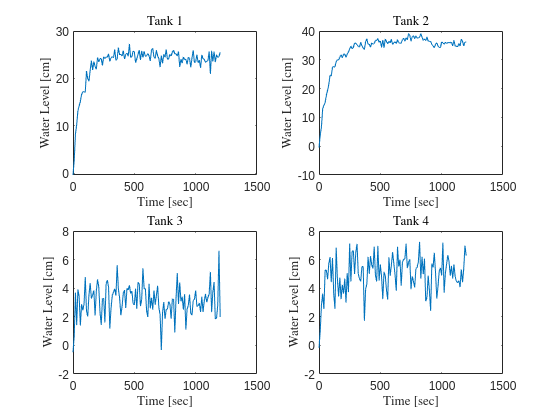

[y1, z1, ~, ~,t] = SimulateStochastic(F, 1,"0%");
figure()

subplot(2,2,1)
plot(t,y1(1, :))
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,2)
plot(t,y1(2, :))
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,3)
plot(t, y1(3, :))
title('Tank 3','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,4)
plot(t, y1(4, :))

title('Tank 4','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

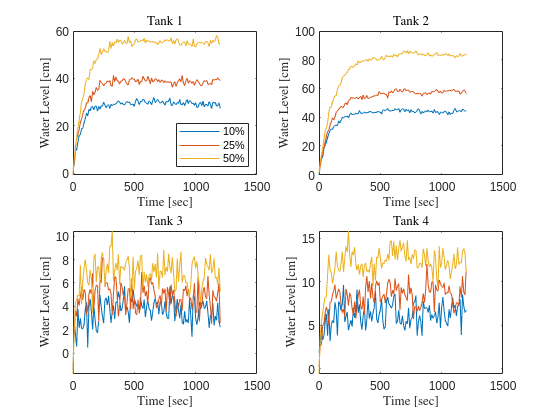


[y1low, z1low, ~, ~,t] = SimulateStochastic(F_d1, 1,"10%");
[y2low, z2low,~, ~,t] = SimulateStochastic(F_d2, 1,"25%");
[y3low, z3low, ~,~,t] = SimulateStochastic(F_d3, 1,"50%");

[y1med, z1med,~,~, t] = SimulateStochastic(F_d1, 2,"10%");
[y2med, z2med,~,~, t] = SimulateStochastic(F_d2, 2,"25%");
[y3med, z3med,~, ~,t] = SimulateStochastic(F_d3, 2,"50%");

[y1high, z1high,~,~, t] = SimulateStochastic(F_d1, 4,"10%");
[y2high, z2high,~, ~,t] = SimulateStochastic(F_d2, 4,"25%");
[y3high, z3high,~, ~,t] = SimulateStochastic(F_d3, 4,"50%");

tl = strcat('Water Level in 4-Tank-System - Low Noise');
figure('Name', tl)
title(tl)
subplot(2,2,1)
plot(t,y1low(1, :))
hold on
plot(t,y2low(1, :))
hold on
plot(t,y3low(1, :))
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,2)
plot(t,y1low(2, :))
hold on
plot(t,y2low(2, :))
hold on
plot(t,y3low(2, :))
hold off
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,3)
plot(t,y1low(3, :))
hold on
plot(t,y2low(3, :))
hold on
plot(t,y3low(3, :))
hold off
title('Tank 3','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,4)
plot(t,y1low(4, :))
hold on
plot(t,y2low(4, :))
hold on
plot(t,y3low(4, :))
hold off
title('Tank 4','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

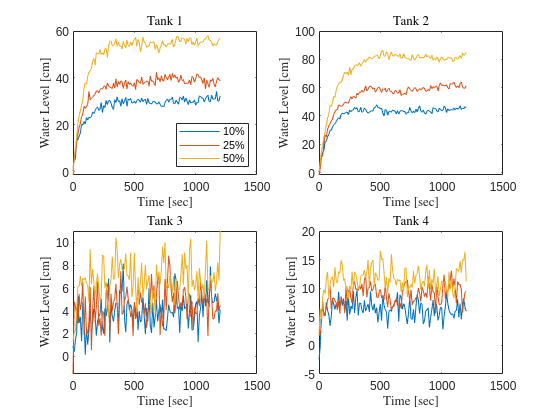



tl = strcat('Water Level in 4-Tank-System - Medium Noise');
figure('Name', tl)
title(tl)
subplot(2,2,1)
plot(t,y1med(1, :))
hold on
plot(t,y2med(1, :))
hold on
plot(t,y3med(1, :))
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,2)
plot(t,y1med(2, :))
hold on
plot(t,y2med(2, :))
hold on
plot(t,y3med(2, :))
hold off
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,3)
plot(t,y1med(3, :))
hold on
plot(t,y2med(3, :))
hold on
plot(t,y3med(3, :))
hold off
title('Tank 3','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,4)
plot(t,y1med(4, :))
hold on
plot(t,y2med(4, :))
hold on
plot(t,y3med(4, :))
hold off
title('Tank 4','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

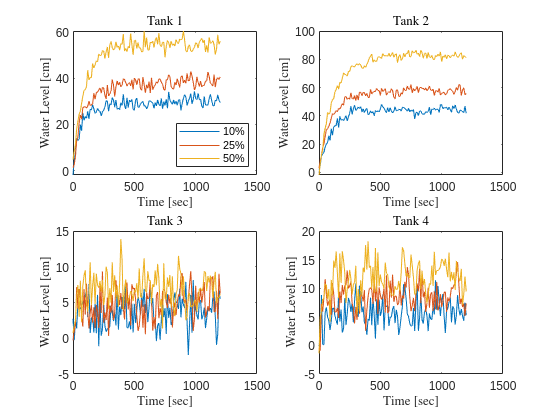



tl = strcat('Water Level in 4-Tank-System - Medium Noise');
figure('Name', tl)
title(tl)
subplot(2,2,1)
plot(t,y1high(1, :))
hold on
plot(t,y2high(1, :))
hold on
plot(t,y3high(1, :))
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,2)
plot(t,y1high(2, :))
hold on
plot(t,y2high(2, :))
hold on
plot(t,y3high(2, :))
hold off
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,3)
plot(t,y1high(3, :))
hold on
plot(t,y2high(3, :))
hold on
plot(t,y3high(3, :))
hold off
title('Tank 3','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,4)
plot(t,y1high(4, :))
hold on
plot(t,y2high(4, :))
hold on
plot(t,y3high(4, :))
hold off
title('Tank 4','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

### 3.3 In all cases compute and plot (in appropriate plots) the normalized steps

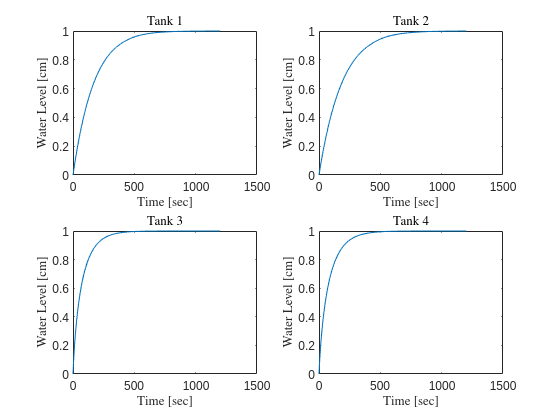

F1 = F(1); F2 = F(2); F3= F(3); F4 = F(4);
F_d11 = [1.1*F1; F2; F3; F4];
F_d12 = [F1; 1.1 * F2; F3; F4];

F_d21 = [1.25*F1; F2; F3; F4];
F_d22 = [F1; 1.25*F2; F3; F4];

F_d31 = [1.5*F1; F2; F3; F4];
F_d32 = [F1; 1.5*F2; F3; F4];


F_diff1 = F_d1 - F;
F_diff11 = F_diff1(1);
% F_diff11(2) = 0.0;
F_diff12 = F_diff1(2);
% 3; FF_diff12(1) = 0.0;

F_diff2 = F_d2 - F;
F_diff21 = F_diff2(1);
% F_diff21(2) = 0.0;
F_diff22 = F_diff2(2);
% F_diff22(1) = 0.0;

F_diff3 = F_d3 - F;
F_diff31 = F_diff3(1);
% %F_diff31(2) = 0.0;
F_diff32 = F_diff3(2);
%F_diff32(1) = 0.0;

[y1low, z1low,~,~, t] = SimulateStochastic(F_d11, 2,"10%");
[y2low, z2low,~,~, t] = SimulateStochastic(F_d21, 2,"25%");
[y3low, z3low,~, ~,t] = SimulateStochastic(F_d31, 2,"50%");

[y1low2, z1low2,~,~, t] = SimulateStochastic(F_d12, 2,"10%");
[y2low2, z2low2,~,~, t] = SimulateStochastic(F_d22, 2,"25%");
[y3low2, z3low2,~, ~,t] = SimulateStochastic(F_d32, 2,"50%");

[y1med, z1med,~,~, t] = SimulateStochastic(F_d11, 2,"10%");
[y2med, z2med,~,~, t] = SimulateStochastic(F_d21, 2,"25%");
[y3med, z3med,~, ~,t] = SimulateStochastic(F_d31, 2,"50%");

[y1med2, z1med2,~,~, t] = SimulateStochastic(F_d12, 2,"10%");
[y2med2, z2med2,~,~, t] = SimulateStochastic(F_d22, 2,"25%");
[y3med2, z3med2,~, ~,t] = SimulateStochastic(F_d32, 2,"50%");

[y1high, z1high,~,~, t] = SimulateStochastic(F_d11, 4,"10%");
[y2high, z2high,~, ~,t] = SimulateStochastic(F_d21, 4,"25%");
[y3high, z3high,~, ~,t] = SimulateStochastic(F_d31, 4,"50%");

[y1high2, z1high2,~,~, t] = SimulateStochastic(F_d12, 4,"10%");
[y2high2, z2high2,~, ~,t] = SimulateStochastic(F_d22, 4,"25%");
[y3high2, z3high2,~, ~,t] = SimulateStochastic(F_d32, 4,"50%");

tl = strcat('Normalized Water Level in 4-Tank-System - Deterministics');
figure('Name', tl)
title(tl)
subplot(2,2,1)
plot(T1,(H(:, 1)/H(end, 1))/1)
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,2)
plot(T1,(H(:, 2) / H(end, 2))/1)
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,3)
plot(T1,(H(:, 3) / H(end, 3))/1)
title('Tank 3','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(2,2,4)
plot(T1,(H(:, 4) / H(end, 4))/1)
title('Tank 4','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

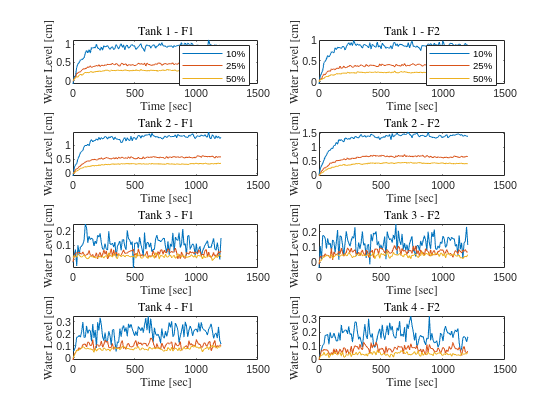






tl = strcat('Normalized Water Level in 4-Tank-System - Low Noise');
figure('Name', tl)
title(tl)
subplot(4,2,1)
plot(t,(y1low(1, :) - H(1, end)) / F_diff11)
hold on
plot(t,(y2low(1, :)  - H(1, end)) / F_diff21)
hold on
plot(t,(y3low(1, :)  - H(1, end)) / F_diff31)
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,2)
plot(t,(y1low2(1, :) - H(1, end)) / F_diff12)
hold on
plot(t,(y2low2(1, :) - H(1, end)) / F_diff22)
hold on
plot(t,(y3low2(1, :) - H(1, end)) / F_diff32)
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,3)
plot(t,(y1low(2, :) - H(2, end)) / F_diff11)
hold on
plot(t,(y2low(2, :) - H(2, end)) / F_diff21)
hold on
plot(t,(y3low(2, :) - H(2, end)) / F_diff31)
hold off
title('Tank 2 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,4)
plot(t,(y1low2(2, :) - H(2, end)) / F_diff12)
hold on
plot(t,(y2low2(2, :) - H(2, end)) / F_diff22)
hold on
plot(t,(y3low2(2, :) - H(2, end)) / F_diff32)
hold off
title('Tank 2 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,5)
plot(t,(y1low(3, :) - H(3, end)) / F_diff11)
hold on
plot(t,(y2low(3, :) - H(3, end)) / F_diff21)
hold on
plot(t,(y3low(3, :) - H(3, end)) / F_diff31)
hold off
title('Tank 3 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,6)
plot(t,(y1low2(3, :) - H(3, end)) / F_diff12)
hold on
plot(t,(y2low2(3, :) - H(3, end)) / F_diff22)
hold on
plot(t,(y3low2(3, :) - H(3, end)) / F_diff32)
hold off
title('Tank 3 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')


subplot(4,2,7)
plot(t,(y1low(4, :) - H(4, end)) / F_diff11)
hold on
plot(t,(y2low(4, :) - H(4, end)) / F_diff21)
hold on
plot(t,(y3low(4, :) - H(4, end)) / F_diff31)
hold off
title('Tank 4 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,8)
plot(t,(y1low2(4, :) - H(4, end)) / F_diff12)
hold on
plot(t,(y2low2(4, :) - H(4, end)) / F_diff22)
hold on
plot(t,(y3low2(4, :) - H(4, end)) / F_diff32)
hold off
title('Tank 4 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

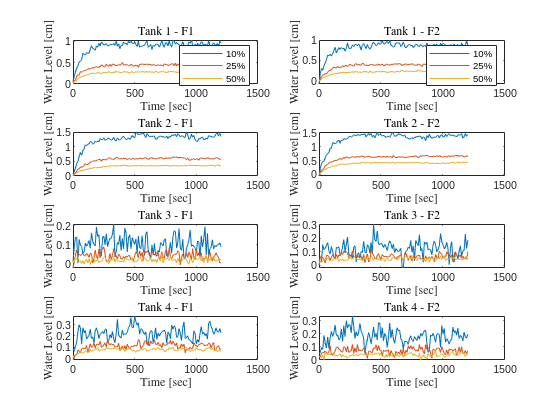


tl = strcat('Normalized Water Level in 4-Tank-System - med Noise');
figure('Name', tl)
title(tl)
subplot(4,2,1)
plot(t,(y1med(1, :) - H(1, end)) / F_diff11)
hold on
plot(t,(y2med(1, :) - H(1, end)) / F_diff21)
hold on
plot(t,(y3med(1, :) - H(1, end)) / F_diff31)
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,2)
plot(t,(y1med2(1, :) - H(1, end)) / F_diff12)
hold on
plot(t,(y2med2(1, :) - H(1, end)) / F_diff22)
hold on
plot(t,(y3med2(1, :) - H(1, end)) / F_diff32)
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,3)
plot(t,(y1med(2, :) - H(2, end)) / F_diff11)
hold on
plot(t,(y2med(2, :) - H(2, end)) / F_diff21)
hold on
plot(t,(y3med(2, :) - H(2, end)) / F_diff31)
hold off
title('Tank 2 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,4)
plot(t,(y1med2(2, :) - H(2, end)) / F_diff12)
hold on
plot(t,(y2med2(2, :) - H(2, end)) / F_diff22)
hold on
plot(t,(y3med2(2, :) - H(2, end)) / F_diff32)
hold off
title('Tank 2 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,5)
plot(t,(y1med(3, :) - H(3, end)) / F_diff11)
hold on
plot(t,(y2med(3, :) - H(3, end)) / F_diff21)
hold on
plot(t,(y3med(3, :) - H(3, end)) / F_diff31)
hold off
title('Tank 3 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,6)
plot(t,(y1med2(3, :) - H(3, end)) / F_diff12)
hold on
plot(t,(y2med2(3, :) - H(3, end)) / F_diff22)
hold on
plot(t,(y3med2(3, :) - H(3, end)) / F_diff32)
hold off
title('Tank 3 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')


subplot(4,2,7)
plot(t,(y1med(4, :)  - H(4, end)) / F_diff11)
hold on
plot(t,(y2med(4, :)  - H(4, end)) / F_diff21)
hold on
plot(t,(y3med(4, :)  - H(4, end)) / F_diff31)
hold off
title('Tank 4 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,8)
plot(t,(y1med2(4, :)  - H(4, end)) / F_diff12)
hold on
plot(t,(y2med2(4, :)  - H(4, end)) / F_diff22)
hold on
plot(t,(y3med2(4, :)  - H(4, end)) / F_diff32)
hold off
title('Tank 4 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

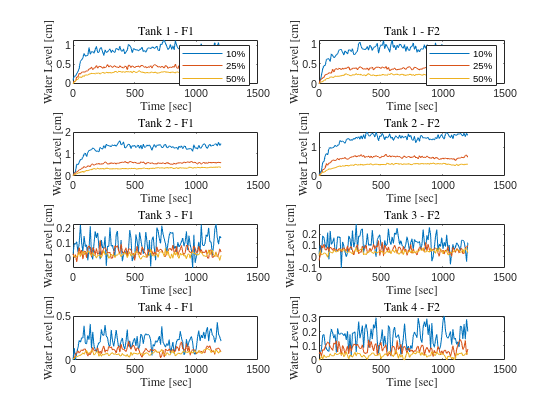




tl = strcat('Normalized Water Level in 4-Tank-System - high Noise');
figure('Name', tl)
title(tl)
subplot(4,2,1)
plot(t,(y1high(1, :)  - H(1, end)) / F_diff11)
hold on
plot(t,(y2high(1, :)  - H(1, end)) / F_diff21)
hold on
plot(t,(y3high(1, :)  - H(1, end)) / F_diff31)
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,2)
plot(t,(y1high2(1, :)  - H(1, end)) / F_diff12)
hold on
plot(t,(y2high2(1, :)  - H(1, end)) / F_diff22)
hold on
plot(t,(y3high2(1, :) - H(1, end)) / F_diff32)
hold off
legend('10%', '25%', '50%', 'Location','southeast')
title('Tank 1 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,3)
plot(t,(y1high(2, :) - H(2, end)) / F_diff11)
hold on
plot(t,(y2high(2, :) - H(2, end)) / F_diff21)
hold on
plot(t,(y3high(2, :) - H(2, end)) / F_diff31)
hold off
title('Tank 2 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,4)
plot(t,(y1high2(2, :) - H(2, end)) / F_diff12)
hold on
plot(t,(y2high2(2, :) - H(2, end)) / F_diff22)
hold on
plot(t,(y3high2(2, :) - H(2, end)) / F_diff32)
hold off
title('Tank 2 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,5)
plot(t,(y1high(3, :) - H(3, end)) / F_diff11)
hold on
plot(t,(y2high(3, :) - H(3, end)) / F_diff21)
hold on
plot(t,(y3high(3, :) - H(3, end)) / F_diff31)
hold off
title('Tank 3 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,6)
plot(t,(y1high2(3, :) - H(3, end)) / F_diff12)
hold on
plot(t,(y2high2(3, :) - H(3, end)) / F_diff22)
hold on
plot(t,(y3high2(3, :) - H(3, end)) / F_diff32)
hold off
title('Tank 3 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')


subplot(4,2,7)
plot(t,(y1high(4, :) - H(4, end)) / F_diff11)
hold on
plot(t,(y2high(4, :) - H(4, end)) / F_diff21)
hold on
plot(t,(y3high(4, :) - H(4, end)) / F_diff31)
hold off
title('Tank 4 - F1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

subplot(4,2,8)
plot(t,(y1high2(4, :) - H(4, end)) / F_diff12)
hold on
plot(t,(y2high2(4, :) - H(4, end)) / F_diff22)
hold on
plot(t,(y3high2(4, :) - H(4, end)) / F_diff32)
hold off
title('Tank 4 - F2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

### 3. 4 From the normalized steps, identify a transfer function for the four tank system (transfer function from u to y).

% F = [300, 00, 250, 250];
% [T, H1, ~] = simulateDeterministic(F, p);
% HNom11 = (H1(:, 1)/H1(end, 1));
% HNom21 = (H1(:, 2)/H1(end, 2));
% F = [0, 300, 250, 250];
% [T, H2, ~] = simulateDeterministic(F, p);
% HNom12 = (H2(:, 1)/H2(end, 1));
% HNom22 = (H2(:, 2)/H2(end, 2));
% tfdata1 = iddata(300*ones(length(HNom11),1),HNom11, 100);
% G11 = tfest(HNom11, 2)
%  tfest(tfdata,2,1,NaN)

% get A, B, C, E matrix of system 
[xs, hs] = computeSteadyState(p, F);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


[A,B,C,Cz,E] = linearize(p, hs);    % continuous

s = tf('s');
inv_helper = C*inv(eye(4)*s-A);
Gyu = inv_helper*B;
Gyd = inv_helper*E;

inv_helper2 = Cz*inv(eye(4)*s-A);
Gzu = inv_helper2 *B;
Gzd = inv_helper2 * E;

### 3. 5 Report the identified linear model estimate from the step responses. Discuss the accuracy of the model and the requirements of a step experiment.

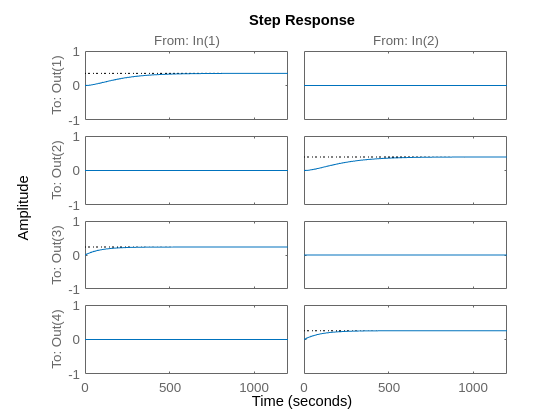

figure()
step(Gyd)

### 3.6 Compute the corresponding impulse response coefficients (Markov paramaters, discrete-time, you choose a sampling time) and plot them in appropriate plots.

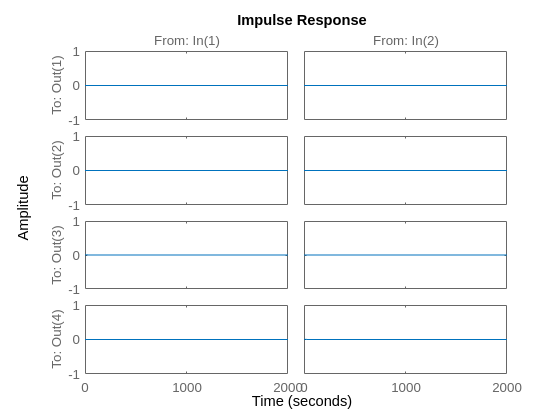

figure()
impulse(Gyd); 


[markovparams,simt] = impulse(Gyd);

## Problem 4 - Linearization and Discretization

### 4.1 Compute continuous-time linearized models for the 3 models developed in Problem 2.

clear all
% get parameters
p = GetParameters();

% flow rate steady state
F = [300, 300, 250, 250];
scale = 1.0;

% simulate deterministic
[tD, yD, zD] = simulateDeterministic(F, p);

% simulate stochastic
[yS, zS,~, ~,tS] = SimulateStochastic(F, scale, '');

% simulate Stochastic with Brownian Motion
[ySB, zSB, tSB] = SimulateStochasticBrown(F);
Ts = 10;

[xs, hs] = computeSteadyState(p, F);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


[A,B,C,Cz,E] = linearize(p, hs);    % continuous



### 4.2 Compute the gains, poles and zeros of these models.

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = C*inv(eye(4)*s-A) * B;

G_zeros = tzero(G)

G_zeros =    -0.0067
   -0.0075


G_poles = pole(G)

G_poles =    -0.0075
   -0.0103
   -0.0067
   -0.0103
   -0.0112
   -0.0075
   -0.0067
   -0.0112



D = zeros(4,2)

D =      0     0
     0     0
     0     0
     0     0


[z1,p1,k1] = ss2zp(A,B,C,D,1) 

z1 =    -0.0067   -0.0075       Inf   -0.0067
   -0.0103   -0.0112       Inf   -0.0075
   -0.0112       Inf       Inf   -0.0112


p1 =    -0.0075
   -0.0067
   -0.0112
   -0.0103


k1 =     0.0015
    0.0000
         0
    0.0011


[z2,p2,k2] = ss2zp(A,B,C,D,2)

z2 =    -0.0067   -0.0075   -0.0075       Inf
   -0.0103   -0.0112   -0.0067       Inf
       Inf   -0.0103   -0.0103       Inf


p2 =    -0.0075
   -0.0067
   -0.0112
   -0.0103


k2 =     0.0000
    0.0018
    0.0008
         0


### 4.3 Compute the continuous-time transfer functions for the continuous-time linearized models.

G_transfer = zpk(G)

G_transfer =
 
  From input 1 to output...
        0.0015258
   1:  ------------
       (s+0.007474)
 
              1.1421e-05
   2:  ------------------------
       (s+0.01034) (s+0.006701)
 
   3:  0
 
        0.0011049
   4:  -----------
       (s+0.01034)
 
  From input 2 to output...
              9.4559e-06
   1:  ------------------------
       (s+0.01123) (s+0.007474)
 
        0.0017888
   2:  ------------
       (s+0.006701)
 
       0.00084181
   3:  -----------
       (s+0.01123)
 
   4:  0
 
Continuous-time zero/pole/gain model.



G_zeros = tzero(G_transfer)

G_zeros =    -0.0067
   -0.0075


G_poles = pole(G_transfer)

G_poles =    -0.0075
   -0.0103
   -0.0067
   -0.0103
   -0.0112
   -0.0075
   -0.0067
   -0.0112


### 4.5 Compute discrete-time state space models using a sampling time of your choice.

Ts = 10;
% get discrete matrices 
% [Phi,Gamma]=css2dsszoh(A,B,Ts)
W = [A,B,E; zeros(4,8)];
W = expm(W*Ts);
Ad = W(1:4,1:4);
Bd = W(1:4, 5:6);
% Bd = [Bd, [0;0;0;0], [0;0;0;0]]
Ed = W(1:4, 7:8);
Cd = C;
Czd = Cz;
Dd = D;

### 4.6 Compute the Markov parameters for these discrete-time state space models and compare them to the the Markov parameters you obtained from the step response experiments

N=100;
H = zeros(4,2,N);

for i=1:N
    H(:,:,i)=Cd*(Ad^(i-1))*Bd;
end
figure()
sys = ss(Ad,Bd,Cd,Dd,1)

sys =
 
  A = 
            x1       x2       x3       x4
   x1    0.928        0   0.1023        0
   x2        0   0.9352        0  0.09493
   x3        0        0   0.8938        0
   x4        0        0        0   0.9018
 
  B = 
           u1      u2
   x1   5.589  0.1689
   x2  0.2051   6.577
   x3       0   3.027
   x4    3.99       0
 
  C = 
             x1        x2        x3        x4
   y1  0.002631         0         0         0
   y2         0  0.002631         0         0
   y3         0         0  0.002631         0
   y4         0         0         0  0.002631
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Sample time: 1 seconds
Discrete-time state-space model.



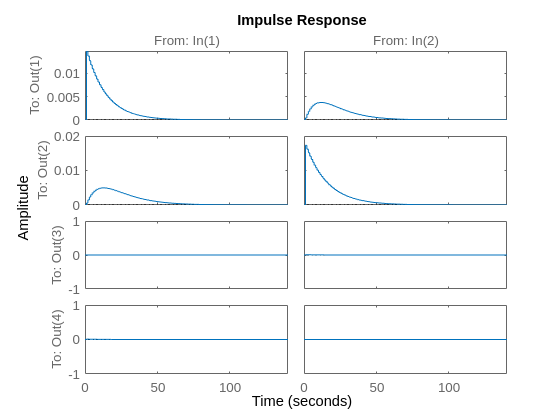

impulse(sys)

## Problem 5 - State Estimation for the Discrete-Time Linear System

### 5.1 Show how the models in Problem 3 and Problem 4 can be represented as linear state space models in discrete time.

% same as 4.5
F = [300, 300, 250, 250];
[y, z, x, d, t] = SimulateStochastic(F, 25,"");

ModelDiscrete = modelDiscrete(Ad, Bd, Cd, Czd, Ed, [0;0;0;0])

ModelDiscrete = struct with fields:
     Ad: [4×4 double]
     Bd: [4×2 double]
     Cd: [4×4 double]
    Czd: [2×4 double]
     Ed: [4×2 double]
     Qk: [2×2 double]
     Rk: [4×4 double]
     Sk: [2×4 double]
     su: 2
     sz: 2
     sx: 4
      r: [100 110 40 40]


kalman = Kalman(Ad, Cd);

### 5.2 Design and evaluate static and dynamic Kalman filters for the linear models identified in Problem 3 and Problem 4. You should simulate the case where the unknown disturbances are stochastic variables but do not contains step changes.

STATIC FILTER

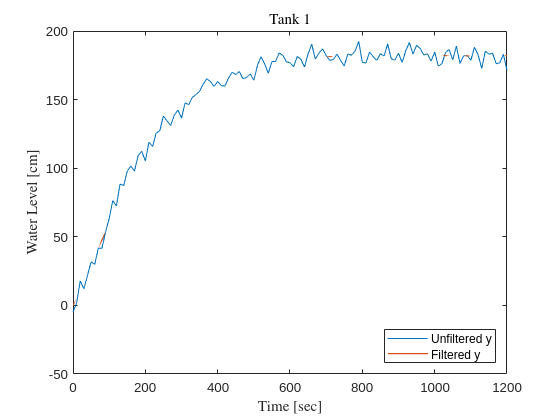

% Noises
N = length(x);
    % Process Noise 
    Q = scale * [10^2 0;0 20^2];
    Lq = chol(Q,'lower');
    w = Lq*randn(2,N);

    % Measurement Noise
    R = 25 * eye(4);
    Lr = chol(R,'lower');
    v = Lr*randn(4,N);

% store y and x in new variables
dy = y;
dx = zeros(4,N);
dx(:,1) = x(:, 1);

du = [F(1); F(2)];


y_est = zeros(4, N);



for k = 1:N-1    
    dx(:,k+1) = Ad*dx(:,k)+Bd*du + Ed*(w(1:2,k)+F(3:4)');
    dy(:,k+1) = Cd*dx(:,k+1) + v(:,k+1);

    e = dy(:,k+1) - Cd*dx(:,k+1);
    
    x_est = dx(:,k+1) + kalman.K_fx*e;
    y_est(:,k+1) = Cd*x_est;
    
end

figure()
plot(t,dy(1,:))
hold on
plot(t,y_est(1,:), 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

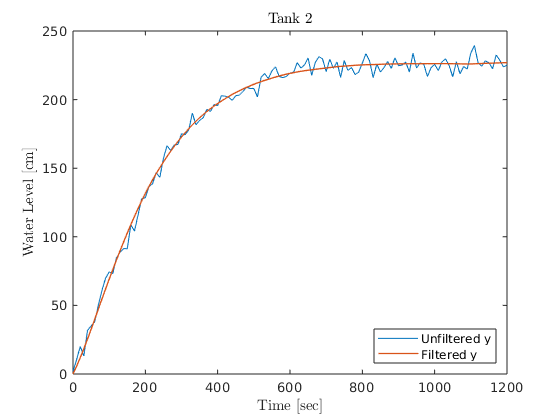


figure()
plot(t,dy(2,:))
hold on 
plot(t,y_est(2,:), 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

### 5.2 Design and evaluate static and dynamic Kalman filters for the linear models identified in Problem 3 and Problem 4. You should simulate the case where the unknown disturbances are stochastic variables but do not contains step changes.

DYNAMIC FILTER

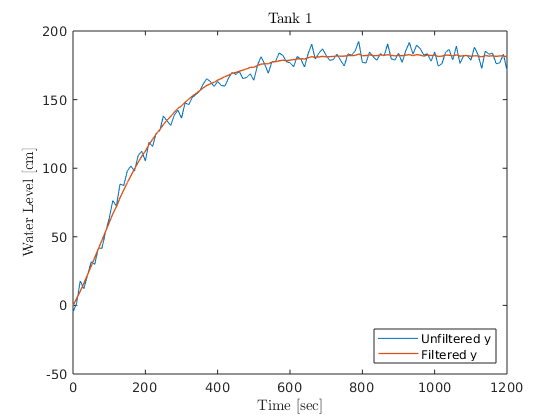

clear P;
N = length(x);
G = eye(4);
Rk = eye(4); 
Qk = 5^2 * eye(4);
S = eye(4);
P1 = dare(Ad',Cd',G*Qk*G',Rk,G*S);

P{1} = P1;

% store y and x in new variables
dy = y;
dx = zeros(4,N);
dx(:,1) = x(:, 1);

du = [F(1); F(2)];


y_est = zeros(4, N);
x_est = zeros(4, N);


for k = 1:N-1    
    % state predictions
    dx(:,k+1) = Ad*dx(:,k)+Bd*du + Ed*(w(1:2,k)+F(3:4)');
    dy(:,k+1) = Cd*dx(:,k+1) + v(:,k+1);
    
    e = dy(:,k+1) - Cd*dx(:,k+1);

    R_e_k = Cd * P{k} * Cd' + Rk;
    R_e_k_inv = inv(R_e_k);

    % compute filtered state and filtered process noise 
    K_fx_k = P{k}*Cd'*R_e_k_inv;
    
    x_est = dx(:,k+1) + K_fx_k*e;
    y_est(:,k+1) = Cd*x_est;
    
    P{k+1} = Ad * P{k} * Ad' + Ed * Qk(1:2, 1:2) * Ed';
   
    
end

figure()
plot(t,dy(1,:))
hold on
plot(t,y_est(1,:), 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

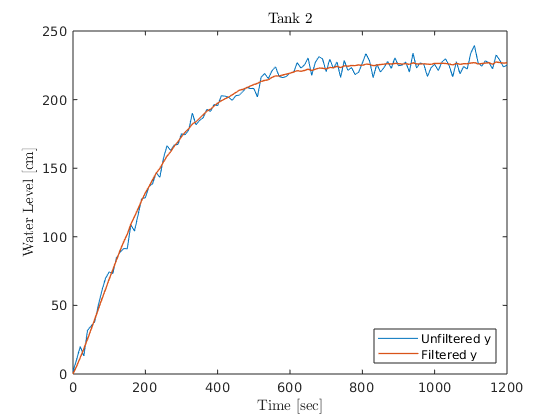


figure()
plot(t,dy(2,:))
hold on 
plot(t,y_est(2,:), 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

### 5. 3 Design and evaluate static and dynamic Kalman filters for the linear models identified in Problem 3 and Problem 4. You should simulate the case where the unknown disturbances are stochastic variables but DO CONTAIN step changes. Design Kalman Filters that do not have steady state offsets.

STATIC FILTER

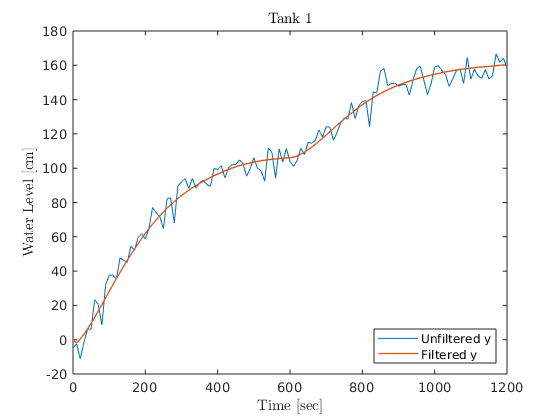

% Noises
N = length(x);
    % Process Noise 
    Q = [10^2 0;0 20^2];
    Lq = chol(Q,'lower');
    w = Lq*randn(2,N);

    % Measurement Noise
    R = 25 * eye(4);
    Lr = chol(R,'lower');
    v = Lr*randn(4,N);
N = length(x);
N_step = round(N/2);

dist = repmat(F(3:4)', 1, N_step);
dist(:, N_step:N) = repmat(F(3:4)' + [150;150], 1, N_step);

y_ss = y(:, end);
dy = y-y_ss;
dx = zeros(4,N);

dx(:,1) = x(:, 1)-x(:, end);

du = [0; 0];


y_est = zeros(4, N);
y_est(:, 1) = y_est(:, 1) - y_ss;

for i = 1:N-1
    dx(:,i+1) = Ad*dx(:,i)+Bd*du + Ed*(w(1:2,i)+dist(:, i));
    dy(:,i+1) = Cd*dx(:,i+1) + v(:,i+1);
end

for k = 1:N-1    
    e = dy(:,k+1) - Cd*dx(:,k+1);
    
    x_est = dx(:,k+1) + kalman.K_fx*e;
    y_est(:,k+1) = Cd*x_est;
    
end

figure()
plot(t,dy(1,:)'+y_ss(1)')
hold on
plot(t,y_est(1,:)+y_ss(1)', 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

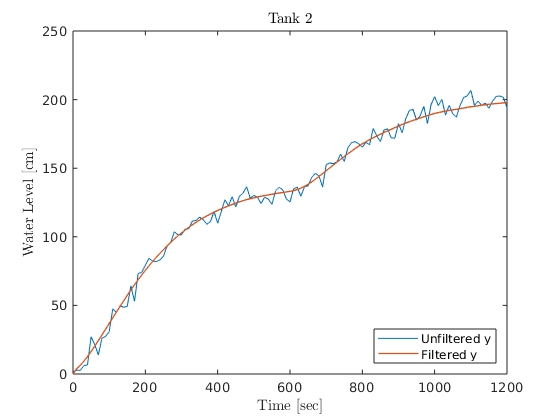


figure()
plot(t,dy(2,:)'+y_ss(2)')
hold on 
plot(t,y_est(2,:)'+y_ss(2)', 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

### 5. 3 Design and evaluate static and dynamic Kalman filters for the linear models identified in Problem 3 and Problem 4. You should simulate the case where the unknown disturbances are stochastic variables but DO CONTAIN step changes. Design Kalman Filters that do not have steady state offsets.

DYNAMIC FILTER

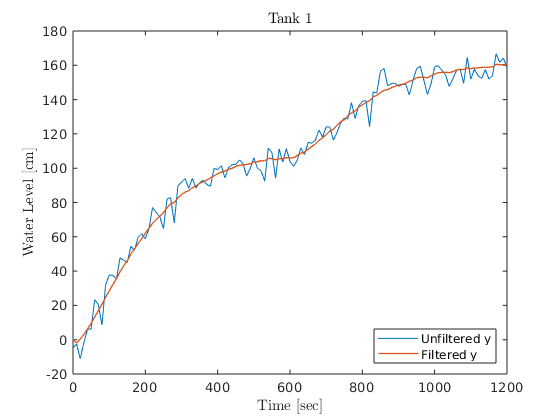

clear P;
N = length(x);
N_step = round(N/2);

dist = repmat(F(3:4)', 1, N_step);
dist(:, N_step:N) = repmat(F(3:4)' + [150;150], 1, N_step);

G = eye(4);
Rk = eye(4); 
Qk = 5^2 * eye(4);
S = eye(4);
P1 = dare(Ad',Cd',G*Qk*G',Rk,G*S);

P{1} = P1;

y_ss = y(:, end);
dy = y-y_ss;
dx = zeros(4,N);

dx(:,1) = x(:, 1)-x(:, end);

du = [0; 0];


y_est = zeros(4, N);
y_est(:, 1) = y_est(:, 1) - y_ss;
x_est = zeros(4, N);

for i = 1:N-1
    % state predictions
    dx(:,i+1) = Ad*dx(:,i)+Bd*du + Ed*(w(1:2,i)+dist(:, i));
    dy(:,i+1) = Cd*dx(:,i+1) + v(:,i+1);
end

for k = 1:N-1    
    
    e = dy(:,k+1) - Cd*dx(:,k+1);

    R_e_k = Cd * P{k} * Cd' + Rk;
    R_e_k_inv = inv(R_e_k);

    % compute filtered state and filtered process noise 
    K_fx_k = P{k}*Cd'*R_e_k_inv;
    
    x_est = dx(:,k+1) + K_fx_k*e;
    y_est(:,k+1) = Cd*x_est;
    
    P{k+1} = Ad * P{k} * Ad' + Ed * Qk(1:2, 1:2) * Ed';
   
    
end

figure()
plot(t,dy(1,:)'+y_ss(1)')
hold on
plot(t,y_est(1,:)+y_ss(1)', 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 1','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

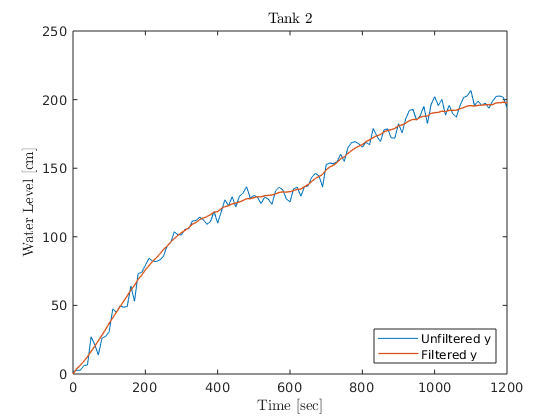


figure()
plot(t,dy(2,:)'+y_ss(2)')
hold on 
plot(t,y_est(2,:)'+y_ss(2)', 'LineWidth',1.0)
hold off
legend('Unfiltered y', 'Filtered y', 'Location','southeast')
title('Tank 2','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

## Problem 6 - QP solver interface

% function x = regulator(H,g,l,u,A,bl,bu,xinit)
%      
%     [x,fval,exitflag,output,lambda] = quadprog(H,g,[A; -A],[bu; -bl],[],[],l,u,xinit,options)
% 
% end


## Problem 7 - Unconstrained MPC

% SETUP 
% same as 4.5 and 5.1
clear dist
F = [300, 300, 250, 250];
dist = repmat(F(3:4)', 1, N);
[y, z, x, d, t] = SimulateStochastic(F, 1,"");
% define seady state of system
y_ss = y(:, end);
x_ss = x(:, end);
u_ss = [0;0];

ModelDiscrete = modelDiscrete(Ad, Bd, Cd, Czd, Ed, y_ss)

ModelDiscrete = struct with fields:
     Ad: [4×4 double]
     Bd: [4×2 double]
     Cd: [4×4 double]
    Czd: [2×4 double]
     Ed: [4×2 double]
     Qk: [2×2 double]
     Rk: [4×4 double]
     Sk: [2×4 double]
     su: 2
     sz: 2
     sx: 4
      r: [76.2350 70.4612 36.7176 34.9154]


kalman = Kalman(Ad, Cd);



### 7.1. Implement a function for design of an Unconstrained MPC based on discrete-time state space models. You should explain in the report how your Matlab function work and its theoretical background.

EXPLICIT IMPLEMENTATION

clear dx dy du
% setup matrices for optimal con3trol problem 
% they are constant -> offline computation
N_pred = 10;


[Lx, Lr, Lu, Ld] = setupUnconstrained(ModelDiscrete,S, Q, N_pred);
setpoint = [];
dx = zeros(4,N);
du = zeros(2,N);
dx(:,1) = x(:, 1);
du(:, 1) = [500;F(2)];
 
y_est = zeros(4, N);
w_est = zeros(4, N);
x_est = zeros(4, N);

% setpoints 
setpoints = []


setpoints =

     []



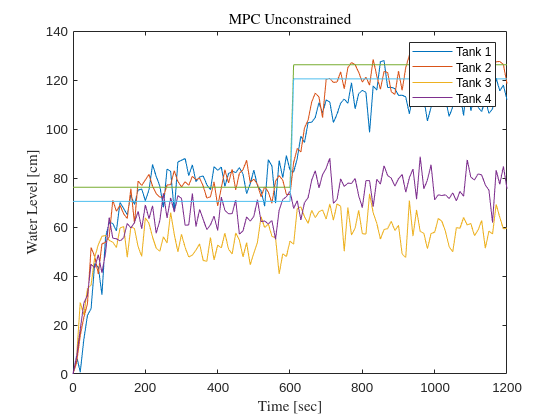

r_set_1 = repmat(ModelDiscrete.r(1:2),1,N_step);
r_set_2 = repmat(ModelDiscrete.r(1:2) + [50, 50],1,N);
r_set = [r_set_1, r_set_2];

i = 1;
for k = 1:N-1   
    setpoints = [setpoints; r_set(i), r_set(i+1)];
    % 1. get deviation variables
    dx(:,k+1) = Ad*dx(:,k)+Bd*du(:, k) + Ed*(w(1:2,k)+dist(:, k));
    dy(:,k+1) = Cd*dx(:,k+1) + v(:,k+1);

    % 2. do the Kalman Filtering 
    e = dy(:,k+1) - Cd*dx(:,k+1);
    
    x_est(:, k) = dx(:,k+1) + kalman.K_fx*e;
    w_est(:, k) = kalman.K_fw * e;
    y_est(:,k) = Cd*x_est(:,k);
    
   
    % 3. get regulation matrices and call qr solver 
    u_opt = Lx * x_est(:, k) + Lr * r_set(i:i+N_pred*2-1)' + Lu * du(:, k) + Ld * w_est(1:2, k);
    du(:, k+1) = u_opt;

    i = i+2;
end
setpoints = [setpoints; r_set(i), r_set(i+1)];
% setpoint = [setpoint; ModelDiscrete.r];
figure()
plot(t,dy)
hold on 
plot(t, setpoints)
hold off
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4')
title('MPC Unconstrained','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

% 
% figure()
% plot(t,dx)
% title('MPC Unconstrained','interpreter','latex')
% xlabel('Time [sec]','interpreter','latex')
% ylabel('Water Level [cm]','interpreter','latex')

### 7.1. Implement a function for design of an Unconstrained MPC based on discrete-time state space models. You should explain in the report how your Matlab function work and its theoretical background.

QP SOLVER IMPLEMENTATION

Overview: 

- predict next states with help of Kalman Filter 

- find the optimal control input for those states

- apply optimal u to system 

- simulate system

- loop

clear dx dy du
% setup matrices for optimal con3trol problem 
% they are constant -> offline computation
% setpoints 
setpoints = []


setpoints =

     []



ModelDiscrete.r = [90,110,80,80];
r_set_1 = repmat(ModelDiscrete.r(1:2),1,N_step);
r_set_2 = repmat(ModelDiscrete.r(1:2) + [50, 50],1,N);
r_set = [r_set_1, r_set_2];

N_pred = 10;

[omega_x, omega_w, gamma] = setupMatrices(ModelDiscrete, N_pred);
setpoint = [];
y_ss = y(:, end);
x_ss = x(:, end);
u_ss = [0;0];
dy = y-y_ss;
dx = zeros(4,N);
du = zeros(2,N);
dx(:,1) = x(:, 1)-x_ss;
du(:, 1) = u_ss;

% u_vec = zeros(2, N);
y_est = zeros(4, N);
w_est = zeros(4, N);
x_est = zeros(4, N);

i = 1;
for k = 1:N-1   
    setpoints = [setpoints; r_set(i), r_set(i+1)];
    % 1. get deviation variables
    dx(:,k+1) = Ad*dx(:,k)+Bd*du(:, k) + Ed*(w(1:2,k)+dist(:, k));
    dy(:,k+1) = Cd*dx(:,k+1) + v(:,k+1);

    % 2. do the Kalman Filtering 
    e = dy(:,k+1) - Cd*dx(:,k+1);
    
    x_est(:, k) = dx(:,k+1) + kalman.K_fx*e;
    w_est(:, k) = kalman.K_fw * e;
    y_est(:,k) = Cd*x_est(:,k);
    
   
    % 3. get regulation matrices and call qr solver 
    [H_z, g_z] = getObjectiveTermOutput(omega_x, omega_w, gamma, N_pred, r_set(i:i+4*N_pred-1), x_est(:, k), w_est(:, k));
    [H_du, g_du] = getObjectiveTermDeltaControl(N_pred, ModelDiscrete, (du(:, k)));
    
    H = H_z + H_du;
    g = g_z + g_du;  

    % Hessian is not symmetric CORRECTION 
    H = (H+H')/2;

    [u_opt,fval,exitflag,output,lambda] = quadprog(H,g)
    du(:, k+1) = u_opt(1:2)-u_ss;

    i = i+2;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 1.0e+03 *

    7.8469
    7.9323
    0.3478
    0.1812
    0.2788
    0.1141
    0.3315
    0.1622
    0.3635
    0.1903


fval = -2.2133e+11

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.986061e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.0233e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   100.3285
    2.1854
  273.2914
  109.6901
  308.7397
  140.8067
  340.3410
  168.8083
  370.8505
  195.5817


fval = -7.3492e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.852175e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.8638e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    25.6727
  -64.6533
  279.5781
  114.5366
  315.2453
  145.7166
  345.8742
  172.8317
  375.7313
  199.0011


fval = -7.0971e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.642628e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6193e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    65.8403
  -57.9869
  285.4219
  122.8194
  319.7696
  153.0264
  349.7795
  179.2981
  379.0452
  204.7529


fval = -7.4711e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.642628e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6659e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    51.7266
  -40.7221
  292.3368
  127.5437
  326.1227
  156.8368
  355.3521
  182.5006
  383.9985
  207.4215


fval = -7.6639e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.642628e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6543e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    68.6082
  -48.5514
  295.5393
  132.9424
  328.6278
  161.7703
  357.4682
  186.8670
  385.7612
  211.3308


fval = -7.8399e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.677552e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6892e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    69.2008
  -36.1551
  299.9806
  137.0946
  332.5400
  165.2417
  360.8769
  189.8707
  388.7520
  213.9238


fval = -8.0216e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.677552e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6659e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    82.3398
  -31.7850
  303.7912
  141.7174
  335.6890
  169.2812
  363.6017
  193.4138
  391.1001
  217.0464


fval = -8.2235e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.665911e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6892e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    98.9605
  -32.9715
  305.4376
  147.3603
  336.7607
  174.4417
  364.4085
  198.0747
  391.6589
  221.2918


fval = -8.3987e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.677552e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6892e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    76.9297
  -26.0926
  307.5482
  149.5690
  338.8969
  176.2862
  366.2194
  199.6710
  393.2464
  222.6699


fval = -8.4128e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.689194e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    85.6044
   -7.8935
  312.5353
  151.5902
  343.2958
  177.6940
  370.1690
  200.7745
  396.8025
  223.4892


fval = -8.6275e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6543e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    91.9144
  -16.1818
  314.6342
  153.7107
  345.0542
  179.6501
  371.7011
  202.4558
  398.1346
  224.9586


fval = -8.7008e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    82.0134
  -29.6988
  313.6014
  154.8963
  344.1779
  180.9532
  370.8337
  203.6637
  397.2981
  226.1117


fval = -8.6218e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6776e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    85.6334
  -17.5472
  314.9250
  156.1569
  345.3027
  181.9117
  371.8225
  204.5094
  398.1668
  226.8407


fval = -8.7175e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    85.1555
   -5.9560
  318.3764
  156.5881
  348.4686
  181.9990
  374.6860
  204.4543
  400.7770
  226.6484


fval = -8.8259e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    82.9703
  -17.2089
  319.1519
  156.6225
  349.2025
  182.1224
  375.3424
  204.5060
  401.3729
  226.6627


fval = -8.7994e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   112.7328
  -16.4846
  319.2919
  159.8309
  348.8206
  185.0910
  374.9487
  207.2384
  400.9123
  229.1946


fval = -8.9686e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.677552e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   115.4104
  -12.3351
  319.2926
  162.9920
  348.6614
  187.9688
  374.6966
  209.8869
  400.5823
  231.6426


fval = -9.0426e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    89.1938
  -10.9641
  319.0739
  163.0800
  348.7936
  188.0318
  374.7525
  209.9438
  400.6293
  231.6923


fval = -8.9439e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    76.4973
   -7.7826
  320.1582
  161.7451
  350.0081
  186.6975
  375.8758
  208.6705
  401.7001
  230.4659


fval = -8.9056e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.677552e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   101.4997
  -10.0926
  320.4247
  163.1069
  349.8765
  187.9841
  375.7645
  209.8459
  401.5556
  231.5520


fval = -9.0208e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   109.9417
  -12.2519
  319.5510
  165.2618
  348.8775
  190.0522
  374.7974
  211.7822
  400.6018
  233.3803


fval = -9.0640e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   101.5881
   -1.5898
  320.6011
  166.0946
  349.9210
  190.6401
  375.6993
  212.2911
  401.4034
  233.8039


fval = -9.0998e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   103.6898
    0.1513
  321.9270
  166.8648
  351.0823
  191.2661
  376.7318
  212.8084
  402.3243
  234.2284


fval = -9.1526e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    74.1115
   -2.9540
  323.0536
  164.3974
  352.5948
  188.9469
  378.1253
  210.6076
  403.6753
  232.1354


fval = -9.0120e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    87.3648
  -14.2503
  322.2122
  163.7274
  351.6733
  188.5090
  377.3396
  210.2277
  402.9750
  231.8246


fval = -8.9998e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    96.4625
   -3.3394
  323.4883
  163.8046
  352.7314
  188.3922
  378.3233
  210.0900
  403.8768
  231.6496


fval = -9.0951e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.747402e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7474e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   107.0970
    0.2601
  324.9198
  164.7557
  353.8739
  189.1628
  379.3529
  210.7436
  404.7904
  232.1996


fval = -9.1917e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   103.6406
  -15.1050
  322.8447
  165.6208
  351.9691
  190.2473
  377.5773
  211.7988
  403.1328
  233.2573


fval = -9.1028e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.747402e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    99.7507
   -6.2941
  322.7386
  165.9451
  351.9127
  190.4473
  377.5082
  212.0042
  403.0618
  233.4500


fval = -9.1185e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.747402e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7474e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   117.3258
    0.4696
  323.5740
  167.8166
  352.3828
  192.0664
  377.9107
  213.4737
  403.3737
  234.7815


fval = -9.2552e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    92.3788
    1.9186
  324.6467
  166.6904
  353.7345
  190.9399
  379.1217
  212.3812
  404.5167
  233.7169


fval = -9.1664e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7474e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    83.2887
  -11.5141
  323.6602
  164.9720
  353.0073
  189.5528
  378.4977
  211.1213
  403.9956
  232.5889


fval = -9.0418e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7474e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   108.7879
   -3.4092
  324.0988
  166.1534
  353.0398
  190.5417
  378.5468
  212.0388
  404.0070
  233.4303


fval = -9.1931e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =    99.9539
   -6.0316
  323.7588
  166.3214
  352.8325
  190.7408
  378.3307
  212.2266
  403.8026
  233.6136


fval = -9.1467e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7474e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   105.7854
  -12.8246
  321.9297
  167.4068
  351.0299
  191.9208
  376.6648
  213.3815
  402.2417
  234.7580


fval = -9.1290e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt =   126.1111
    2.3174
  322.6407
  170.4709
  351.3063
  194.5528
  376.8573
  215.8050
  402.3262
  236.9776


fval = -9.3205e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   80.5619
   -4.5477
  322.1621
  168.4783
  351.5276
  192.7905
  377.0216
  214.1725
  402.5350
  235.4680


fval = -9.0805e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   97.0032
  -15.4447
  319.9636
  168.7972
  349.2784
  193.3336
  375.0014
  214.7575
  400.6737
  236.1057


fval = -9.0706e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  102.6574
   -6.0758
  319.3985
  169.7853
  348.6512
  194.1696
  374.4121
  215.5733
  400.1063
  236.8856


fval = -9.1266e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   98.0784
   -5.5843
  319.0105
  170.1539
  348.3388
  194.5223
  374.1043
  215.9133
  399.8127
  237.2136


fval = -9.1089e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.700835e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7008e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   91.8690
    4.4842
  320.4905
  169.6379
  349.8040
  193.8483
  375.4432
  215.2453
  401.0573
  236.5333


fval = -9.1379e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.724119e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7241e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   79.5482
  -35.4516
  313.9703
  165.3015
  342.5905
  189.1351
  367.2669
  209.4730
  391.7590
  229.6361


fval = -1.1865e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.078006e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.0803e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   89.0179
    9.1912
  315.9457
  167.3296
  345.0482
  191.2687
  370.3996
  212.4142
  395.6256
  233.3513


fval = -2.0625e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.160668e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.1607e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   60.6131
  -28.7384
  311.4618
  160.3698
  339.7376
  183.7271
  363.6930
  203.6555
  387.4106
  223.2858


fval = -2.3107e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.443550e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.4435e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   92.3709
   20.2250
  316.3036
  162.4496
  344.6274
  185.8035
  369.1826
  206.5222
  393.5540
  226.9337


fval = -3.1379e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.123415e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.1234e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   86.5463
  -43.1051
  308.3612
  157.6919
  335.4246
  180.4800
  358.5471
  199.5806
  381.1301
  218.2543


fval = -3.3696e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.406297e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.4063e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  127.0262
   19.9985
  311.6652
  163.9706
  338.7336
  186.4607
  362.6061
  206.2572
  385.7995
  225.4681


fval = -4.1579e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.095476e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.0955e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   75.7092
  -40.8678
  302.7678
  157.3123
  328.9496
  179.0281
  350.8548
  196.9456
  367.9121
  211.6943


fval = -4.3444e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.406297e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3970e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   88.6963
   24.2595
  307.2796
  159.3593
  334.0364
  181.1305
  356.5976
  199.9942
  369.1280
  210.5898


fval = -5.0446e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.104789e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.1048e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
   54.9600
  -50.2606
  297.5123
  149.7827
  322.7776
  170.7336
  339.1299
  185.0394
  375.3355
  209.5728


fval = -5.2141e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.378357e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3597e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  124.0733
   28.0412
  302.7329
  156.1472
  327.6178
  176.6763
  339.5132
  186.7449
  411.5053
  245.4364


fval = -5.9303e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.086163e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.0862e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.0530
   -0.0508
    0.2919
    0.1452
    0.3114
    0.1622
    0.3466
    0.1859
    2.0026
    1.3307


fval = -6.0587e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.378357e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3970e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.0908
    0.0233
    0.2963
    0.1481
    0.3109
    0.1601
    0.3823
    0.2184
    4.1213
    3.5682


fval = -6.6720e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.067536e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.0489e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.0380
   -0.0711
    0.2782
    0.1324
    0.3170
    0.1594
    1.9723
    1.3037
    2.6949
    2.5664


fval = -6.7861e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.341105e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3411e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.1310
    0.0359
    0.2798
    0.1350
    0.3532
    0.1948
    4.0915
    3.5440
    0.6308
    0.3421


fval = -7.4720e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.086163e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.0489e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.0110
   -0.0876
    0.2840
    0.1321
    1.9429
    1.2795
    2.6646
    2.5415
    0.6135
    0.3314


fval = -7.4756e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.322478e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3225e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.0981
    0.0303
    0.3212
    0.1658
    4.0618
    3.5166
    0.6005
    0.3144
    0.5929
    0.3076


fval = -8.1257e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.030283e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.0117e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.0136
   -0.0924
    1.9095
    1.2487
    2.6351
    2.5141
    0.5831
    0.3036
    0.5990
    0.3117


fval = -8.1271e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.322478e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.2666e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    0.1640
    0.0614
    4.0293
    3.4908
    0.5700
    0.2900
    0.5618
    0.2826
    0.6108
    0.3234


fval = -8.8214e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.993030e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.0117e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    1.6285
    1.0077
    2.6029
    2.4886
    0.5546
    0.2811
    0.5694
    0.2883
    0.6143
    0.3262


fval = -8.7290e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.322478e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3039e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
1.0e+03 *

    2.3519
    2.2932
    0.5248
    0.2559
    0.5387
    0.2631
    0.5827
    0.3004
    0.6213
    0.3321


fval = -5.8927e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.154840e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1362e-07
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  301.9957
   62.2849
  511.2194
  243.9884
  551.8908
  277.8988
  589.5670
  308.6995
  627.0948
  339.3042


fval = -2.2494e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.214235e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2142e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  260.8478
   60.4872
  520.7504
  249.2411
  560.9637
  282.2747
  597.5208
  312.2430
  634.2019
  342.1667


fval = -2.2665e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.214235e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.1910e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  243.5968
   58.6953
  528.7301
  250.9649
  568.4474
  283.4763
  604.2158
  312.9618
  640.2717
  342.4948


fval = -2.2849e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.190952e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.1910e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  255.1404
   64.5069
  536.8627
  252.4037
  575.7177
  284.3321
  610.7976
  313.3882
  646.2513
  342.5601


fval = -2.3251e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.237518e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2375e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  273.2621
   59.8966
  542.5115
  254.6583
  580.5832
  286.1947
  615.1767
  314.8336
  650.1863
  343.6712


fval = -2.3586e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.214235e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2142e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  292.5990
   58.5238
  546.3010
  258.1420
  583.6765
  289.2519
  617.9051
  317.4680
  652.5725
  345.9578


fval = -2.3917e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.237518e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2375e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  321.9542
   66.2562
  549.9553
  263.7809
  586.4346
  294.2085
  620.2770
  321.8750
  654.5674
  349.8924


fval = -2.4415e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.260801e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  266.7189
   65.0517
  552.8455
  262.5317
  589.8485
  292.8914
  623.2939
  320.5015
  657.3642
  348.4796


fval = -2.4115e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.284084e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2841e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  301.1687
   67.7749
  555.8701
  264.5944
  592.1044
  294.6321
  625.3501
  321.9814
  659.1830
  349.7382


fval = -2.4507e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.284084e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  324.2927
   85.5372
  560.8903
  268.0472
  596.2906
  297.3754
  629.0880
  324.3145
  662.5004
  351.6986


fval = -2.5010e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.307367e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  300.9301
   73.4924
  562.7577
  268.3889
  598.2865
  297.7261
  630.8298
  324.5109
  664.0781
  351.7921


fval = -2.4866e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2841e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  304.9143
   73.7116
  564.6183
  268.8628
  599.9263
  298.0696
  632.3117
  324.7422
  665.4193
  351.9310


fval = -2.4969e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  335.9584
   75.6516
  565.8362
  272.2749
  600.5108
  301.1582
  632.7920
  327.5380
  665.7526
  354.4779


fval = -2.5316e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.260801e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2608e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  306.7513
   85.1159
  568.5557
  271.8711
  603.4052
  300.5203
  635.3710
  326.8320
  668.1267
  353.7012


fval = -2.5254e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  303.0460
   78.4644
  570.0504
  270.7121
  604.8697
  299.4480
  636.7327
  325.7634
  669.4074
  352.6506


fval = -2.5215e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  304.8186
   78.7287
  571.7404
  269.6791
  606.4419
  298.4040
  638.2029
  324.7295
  670.7859
  351.6269


fval = -2.5259e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  352.9096
   71.3894
  570.8955
  274.0580
  604.8689
  302.6098
  636.7247
  328.6341
  669.2940
  355.2901


fval = -2.5628e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.307367e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  349.7487
   88.3722
  572.2948
  277.3294
  606.0714
  305.3649
  637.6965
  331.1301
  670.0842
  357.5377


fval = -2.5832e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.284084e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  319.8470
   83.1951
  572.6488
  276.9811
  606.7916
  305.0701
  638.2915
  330.8163
  670.6363
  357.2193


fval = -2.5607e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.284084e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  345.2436
  100.4640
  576.2036
  278.9714
  609.6607
  306.5415
  640.8913
  332.0513
  672.9589
  358.2266


fval = -2.6046e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  315.2145
   88.3760
  576.9598
  277.2978
  610.8023
  305.0809
  641.9146
  330.6351
  673.9430
  356.8730


fval = -2.5760e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  341.2929
   87.3287
  577.5201
  278.4035
  610.9378
  306.1013
  642.0583
  331.5562
  674.0405
  357.7126


fval = -2.5979e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.4005e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  352.8563
   81.3865
  576.1685
  280.7729
  609.4491
  308.4381
  640.6446
  333.7544
  672.6700
  359.8038


fval = -2.6043e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.307367e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  306.1507
   85.9066
  576.3563
  277.8905
  610.3388
  305.6844
  641.4498
  331.2061
  673.4974
  357.4210


fval = -2.5682e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  320.6077
   90.1231
  577.9983
  276.5946
  611.7167
  304.3596
  642.7843
  329.9324
  674.7621
  356.1837


fval = -2.5823e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  338.7338
   90.5516
  579.4340
  277.1580
  612.7812
  304.8123
  643.7736
  330.2914
  675.6507
  356.4647


fval = -2.6012e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3074e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  313.9290
   82.2823
  579.5102
  275.0297
  613.2511
  302.9233
  644.2169
  328.5251
  676.1201
  354.8182


fval = -2.5747e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  313.9548
   89.5726
  581.7705
  272.8345
  615.4198
  300.6916
  646.2698
  326.3902
  678.0711
  352.7535


fval = -2.5805e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  333.7925
   84.7214
  582.8263
  272.7053
  616.1386
  300.5854
  646.9724
  326.2441
  678.7178
  352.5839


fval = -2.5947e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  352.2262
   86.9005
  583.6603
  274.4493
  616.5995
  302.1407
  647.3716
  327.6458
  679.0293
  353.8530


fval = -2.6159e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3772e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  316.4627
   82.9150
  583.6701
  272.3720
  617.1488
  300.2464
  647.8610
  325.8810
  679.5399
  352.2059


fval = -2.5841e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  327.7784
   83.6941
  584.3265
  271.5363
  617.6410
  299.4364
  648.3654
  325.1157
  680.0292
  351.4772


fval = -2.5922e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  335.5496
   82.4270
  584.6157
  271.4604
  617.8096
  299.3703
  648.5392
  325.0431
  680.1907
  351.4017


fval = -2.5976e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.4005e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  312.3545
   78.4362
  584.8677
  268.7836
  618.4446
  296.9155
  649.1577
  322.7600
  680.8394
  349.2716


fval = -2.5736e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  324.4144
   80.2926
  585.7871
  267.6136
  619.1830
  295.7704
  649.9001
  321.6781
  681.5574
  348.2400


fval = -2.5828e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3772e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  336.5887
   75.7401
  585.6479
  268.0020
  618.8811
  296.1966
  649.6387
  322.0719
  681.3052
  348.6148


fval = -2.5892e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  329.2669
   79.7832
  586.4318
  267.5405
  619.7158
  295.6785
  650.3981
  321.5655
  682.0157
  348.1116


fval = -2.5879e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  348.5003
   74.2800
  585.3887
  269.1676
  618.4426
  297.3116
  649.2253
  323.1093
  680.8899
  349.5891


fval = -2.5987e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.4005e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  337.8790
   77.4810
  584.8134
  269.5539
  618.0359
  297.6553
  648.8180
  323.4523
  680.5052
  349.9249


fval = -2.5922e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  334.6801
   76.3823
  584.2341
  269.6540
  617.5401
  297.7887
  648.3559
  323.5973
  680.0787
  350.0811


fval = -2.5877e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  358.7083
   78.6991
  583.6475
  272.4376
  616.5818
  300.3794
  647.4411
  326.0174
  679.1550
  352.3518


fval = -2.6105e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3772e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  341.9526
   88.5116
  584.7568
  273.0321
  617.7967
  300.7494
  648.4874
  326.3175
  680.0955
  352.5763


fval = -2.6098e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  330.5052
   87.3826
  585.8095
  272.1749
  618.9449
  299.9100
  649.5344
  325.4907
  681.0799
  351.7640


fval = -2.6028e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3306e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  339.3726
   83.3137
  586.2082
  272.2411
  619.1930
  300.0034
  649.7768
  325.5537
  681.2988
  351.8097


fval = -2.6082e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3772e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  309.0996
   74.6225
  585.4289
  269.2090
  618.9831
  297.3236
  649.6225
  323.0982
  681.2497
  349.5592


fval = -2.5725e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3772e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  309.6322
   84.9221
  587.5601
  266.3048
  621.0567
  294.4073
  651.6170
  320.3484
  683.1709
  346.9323


fval = -2.5780e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.330650e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  342.4963
   68.9678
  586.1546
  267.2683
  619.2974
  295.5744
  650.0551
  321.4665
  681.7078
  348.0371


fval = -2.5895e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  341.8085
   81.1138
  586.6284
  268.0415
  619.7162
  296.1229
  650.4102
  321.9734
  682.0119
  348.4861


fval = -2.5991e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  354.6381
   76.7903
  585.7737
  270.2218
  618.6763
  298.2413
  649.4146
  323.9525
  681.0306
  350.3550


fval = -2.6083e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  299.5123
   82.7490
  587.0757
  266.1632
  620.7460
  294.3212
  651.3154
  320.2819
  682.8981
  346.8860


fval = -2.5680e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.4005e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  324.0007
   82.0209
  589.0358
  264.7863
  622.2885
  292.9686
  652.8242
  318.9625
  684.3239
  345.5978


fval = -2.5873e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  342.6072
   75.7765
  589.2702
  265.4015
  622.2376
  293.6087
  652.7970
  319.5350
  684.2786
  346.1251


fval = -2.5991e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3772e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  354.6634
   74.1330
  588.5463
  267.4483
  621.3344
  295.5650
  651.9296
  321.3648
  683.4198
  347.8506


fval = -2.6093e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  340.7286
   68.2794
  586.3696
  268.2508
  619.4777
  296.4798
  650.1788
  322.2842
  681.7893
  348.7827


fval = -2.5913e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.4005e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  326.7159
   65.4727
  584.0893
  267.8520
  617.5765
  296.2525
  648.4322
  322.1679
  680.2019
  348.7625


fval = -2.5714e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.377216e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.4005e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  337.8443
   82.2703
  585.2119
  268.3287
  618.4543
  296.4451
  649.2443
  322.3347
  680.9360
  348.8763


fval = -2.5928e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  310.4937
   66.6149
  583.5460
  266.0799
  617.3573
  294.6185
  648.2599
  320.6889
  680.1002
  347.4112


fval = -2.5545e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.353933e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 20×1
  366.3177
   81.4913
  584.5386
  269.9186
  617.4060
  297.9742
  648.3006
  323.7813
  680.0232
  350.2532


fval = -2.6136e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.307367e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3539e-08
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [20×1 double]
      upper: [20×1 double]


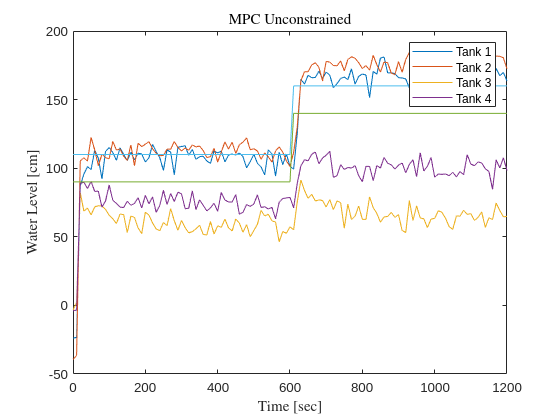

setpoints = [setpoints; r_set(i), r_set(i+1)];

figure()
plot(t,dy)
hold on 
plot(t, setpoints)
hold off
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4')
title('MPC Unconstrained','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

## Problem 8 - Input Constrained MPC

% Boundaries
uMin = [   0.0;   0.0 ];      	% [cm^3/s]	:   input lower bound
uMax = [ 500.0; 500.0 ];        % [cm^3/s] 	:   input upper bound
dMin = [   0.0;   0.0 ];        % [cm^3/s]	:   disturbance lower bound
dMax = [ 100.0; 100.0 ];        % [cm^3/s]	:   disturbance lower bound



clear dx dy du
N_pred = 4;
[omega_x, omega_w, gamma] = setupMatrices(ModelDiscrete, N_pred);

y_ss = y(:, end);
x_ss = x(:, end);
u_ss = [0;0];
dy = y-y_ss;
dx = zeros(4,N);
du = zeros(2,N);
dx(:,1) = x(:, 1)-x_ss;
du(:, 1) = u_ss;

ModelDiscrete.r = [90,110,80,80];
r_set_1 = repmat(ModelDiscrete.r(1:2),1,N_step);
r_set_2 = repmat(ModelDiscrete.r(1:2) + [50, 50],1,N);
r_set = [r_set_1, r_set_2];

% u_vec = zeros(2, N);
y_est = zeros(4, N);
w_est = zeros(4, N);
x_est = zeros(4, N);

UMin = repmat(uMin, N_pred, 1);
UMax = repmat(uMax, N_pred, 1);
DMin = repmat(dMin, N_pred, 1);
DMax = repmat(dMax, N_pred, 1);

Aeq = [];
beq = [];
lb = UMin;
ub = UMax;
x0 = [];

i = 1;
for k = 1:N-1    
    % 1. get deviation variables
    dx(:,k+1) = Ad*dx(:,k)+Bd*du(:, k) + Ed*(w(1:2,k)+dist(:, k));
    dy(:,k+1) = Cd*dx(:,k+1) + v(:,k+1);

    % 2. do the Kalman Filtering 
    e = dy(:,k+1) - Cd*dx(:,k+1);
    
    x_est(:, k) = dx(:,k+1) + kalman.K_fx*e;
    w_est(:, k) = kalman.K_fw * e;
    y_est(:,k) = Cd*x_est(:,k);
    
   
    % 3. get regulation matrices and call qr solver 
    [H_z, g_z] = getObjectiveTermOutput(omega_x, omega_w, gamma, N_pred, r_set(i:i+4*N_pred-1), x_est(:, k), w_est(:, k));
    [H_du, g_du] = getObjectiveTermDeltaControl(N_pred, ModelDiscrete, (du(:, k)));
    
    H = H_z + H_du;
    g = g_z + g_du;  

    % Hessian is not symmetric CORRECTION 
    H = (H+H')/2;
    
    % check if positive definite
    try chol(H)
        disp('Matrix is symmetric positive definite.')
    catch ME
        disp('Matrix is not symmetric positive definite')
    end

    [u_opt,fval,exitflag,output,lambda] = quadprog(H,g,[],[],[],[],lb,ub,[])
    du(:, k+1) = u_opt(1:2)-u_ss;

    i = i+2;
end

ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   500
   500
   500
   500
   500
   500
   500
   500


fval = -2.6047e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.862645e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.413788e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.8626e-09
    constrviolation: 0
         iterations: 18
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -2.3561e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.303852e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.538444e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 2.785328e-16, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.2881e-05
    constrviolation: 1.4211e-12
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -2.1063e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.117587e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.245449e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 1.364242e-16, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.4800e-06
    constrviolation: 6.8212e-13
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.8707e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.862645e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.076671e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 5.286438e-16, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.9607e-05
    constrviolation: 2.7853e-12
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.6413e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 9.313226e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.560818e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 5.115908e-17, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.7264e-06
    constrviolation: 2.8422e-13
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.4189e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.334135e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.069428e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 2.842171e-17, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.7379e-07
    constrviolation: 1.7053e-13
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   500
   500
   500
   500
   500
   500
   500
   500


fval = -1.2061e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 6.472692e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.011471e-19, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.4727e-08
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   500
   500
   500
   500
   500
   500
   500
   500


fval = -1.0035e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328306e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.682041e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-09
    constrviolation: 0
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -8.1072e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 9.313226e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.517662e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3303e-06
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -6.2207e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵9.221545e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7035e-05
    constrviolation: 0
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -4.4665e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.603059e-12, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 1.136868e-17, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.8151e-08
    constrviolation: 5.6843e-14
         iterations: 14
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  403.6262
  500.0000
  255.9119


fval = -2.7963e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.910383e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.956870e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.4528e-05
    constrviolation: 0
         iterations: 11
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  451.1014
  435.2233
  184.2045
  362.3023
  217.3839
  409.1824
  260.4012


fval = -1.3514e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328273e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.589952e-13, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 11
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  165.1923
    0.0000
  327.0801
  157.4173
  370.3158
  225.8655
  417.1360
  267.0664


fval = -5.1571e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.246609e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.067480e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.4321e-06
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   54.9107
    0.0000
  336.5092
  148.1516
  381.2023
  232.5607
  424.1384
  269.8660


fval = -4.5005e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.386969e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.974809e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.3653e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   55.4039
    0.0000
  343.4512
  132.6384
  387.7031
  237.2412
  429.1741
  274.2926


fval = -4.5716e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.165221e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.703191e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.1588e-07
    constrviolation: 0
         iterations: 9
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   89.2846
    0.0000
  348.9491
  127.3050
  392.1055
  244.5393
  433.1908
  281.1530


fval = -4.9216e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 5.820766e-15,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.845122e-23, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   96.1410
    0.0000
  353.5872
  129.4917
  396.0396
  251.2385
  436.9938
  287.3662


fval = -5.1033e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.304270e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.392402e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.9607e-08
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   73.5004
    0.0000
  357.3242
  130.8948
  399.7088
  254.2795
  440.3364
  290.1153


fval = -5.0270e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.199324e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.234057e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.8866e-08
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   64.7306
    0.0000
  361.8747
  135.1650
  404.1239
  255.3717
  444.2062
  290.9465


fval = -5.0679e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.203339e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.455772e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.3149e-08
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   92.4144
    0.0000
  365.1112
  142.8903
  406.7385
  258.9861
  446.5552
  294.2037


fval = -5.3902e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.220446e-16, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1642e-10
    constrviolation: 0
         iterations: 13
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  103.0954
    0.0000
  366.7612
  150.9526
  407.9793
  263.1229
  447.8740
  298.0020


fval = -5.5697e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.236679e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.121234e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.4385e-06
    constrviolation: 0
         iterations: 12
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   98.4724
    0.0000
  370.0586
  167.7814
  411.1254
  265.4721
  450.8254
  299.9228


fval = -5.6962e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 5.804101e-15,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.698814e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.3997e-08
    constrviolation: 0
         iterations: 12
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  103.3214
    0.0000
  373.3188
  186.1150
  414.1732
  267.5902
  453.5897
  301.6100


fval = -5.9066e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.310645e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.376944e-12, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.9740e-09
    constrviolation: 0
         iterations: 13
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   75.8306
    0.0000
  376.0817
  196.1214
  417.2173
  266.1151
  456.4205
  299.9716


fval = -5.7869e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.291531e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.793071e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.4002e-09
    constrviolation: 0
         iterations: 9
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   89.5671
    0.0000
  376.5761
  198.1154
  417.5780
  266.4091
  456.5600
  300.2176


fval = -5.9151e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.759968e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.693138e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.1218e-05
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  101.5438
    0.0000
  379.1212
  211.7047
  419.8321
  267.1162
  458.7811
  300.6423


fval = -6.1382e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164797e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.006768e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3446e-08
    constrviolation: 0
         iterations: 11
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  114.1747
    0.0000
  381.6489
  229.5005
  422.0657
  268.6868
  460.9543
  301.8410


fval = -6.4031e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164643e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.880546e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.8396e-08
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  110.0960
    0.0000
  380.3593
  232.0206
  420.8448
  270.2351
  459.8837
  303.3311


fval = -6.3729e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.160300e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.074711e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.6180e-06
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  107.9231
    6.9830
  381.0745
  235.5790
  421.5559
  270.8136
  460.4940
  303.8311


fval = -6.4354e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328437e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.132310e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3174e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  126.5763
   17.7524
  382.7449
  237.9792
  422.8228
  272.8775
  461.6536
  305.8005


fval = -6.7171e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.909867e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.126128e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3213e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  102.4430
   18.0344
  384.5504
  236.9769
  424.8003
  271.8143
  463.6018
  304.8054


fval = -6.5387e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.491360e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.126075e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3275e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   92.9490
    4.2796
  384.0232
  235.2677
  424.5350
  270.3780
  463.1673
  303.4392


fval = -6.3479e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.492376e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.144400e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3267e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  119.5261
   13.9533
  385.0223
  236.7144
  425.1155
  271.6344
  463.6672
  304.5190


fval = -6.6601e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.490605e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.126823e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3285e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  110.9076
   10.9649
  385.1227
  236.9948
  425.2416
  271.9045
  463.9731
  304.8303


fval = -6.5767e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328234e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.127968e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3289e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  116.4200
    4.5979
  383.5734
  238.2490
  423.7101
  273.2416
  462.4697
  306.1105


fval = -6.5730e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.310984e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.142229e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3241e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  138.1666
   20.9702
  384.7736
  241.6685
  424.4524
  276.2569
  463.1936
  308.9072


fval = -6.9243e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.909821e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125823e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3264e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   92.4903
   11.6741
  384.5733
  239.4791
  424.8534
  274.2457
  463.6724
  307.1004


fval = -6.4546e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.489787e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.127635e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3277e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  108.2658
    1.7091
  382.4826
  239.8283
  422.8039
  274.8109
  461.4291
  307.6232


fval = -6.4903e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.146832e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1657e-10
    constrviolation: 0
         iterations: 4
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  114.8983
   11.5194
  382.1614
  240.8924
  422.3512
  275.7416
  461.1339
  308.4614


fval = -6.6117e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328217e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.127753e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3199e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  110.6291
   11.7815
  381.9951
  241.2678
  422.2235
  276.0750
  461.0518
  308.8526


fval = -6.5803e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.909884e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.127632e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3195e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  105.4208
   21.4874
  383.8082
  240.6690
  424.0166
  275.3139
  462.6826
  308.0937


fval = -6.6212e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.492601e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125769e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3251e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  114.7576
    8.6075
  382.3990
  241.5660
  422.5640
  276.3555
  461.2949
  309.1714


fval = -6.6068e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328440e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.129978e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3205e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   92.7465
    9.8584
  381.9019
  239.8987
  422.4038
  274.8059
  461.2009
  307.6270


fval = -6.4032e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.909881e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.128720e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3200e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  102.4153
   19.2236
  383.8099
  239.0840
  424.1454
  273.8440
  462.6798
  306.6890


fval = -6.5608e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.491481e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125955e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3255e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   97.1843
   19.6683
  386.0428
  237.1765
  426.3243
  271.9154
  464.8049
  304.8618


fval = -6.5355e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328461e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125899e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3323e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  133.6780
   11.7095
  385.4610
  239.9528
  425.2459
  274.6761
  463.7947
  307.4837


fval = -6.8185e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.745650e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.127665e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3289e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  130.9069
   19.7852
  385.7069
  242.2374
  425.3580
  276.7505
  464.1457
  309.3859


fval = -6.8807e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.327713e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125928e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3293e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  130.2125
   20.1479
  385.5233
  244.2424
  425.1511
  278.6314
  463.8915
  311.2247


fval = -6.9018e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328451e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125905e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3286e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   92.4118
   20.1371
  386.4806
  241.3628
  426.6136
  275.8499
  465.2076
  308.5580


fval = -6.5654e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328464e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125877e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3332e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  117.9066
   17.3875
  386.9202
  241.7169
  426.7846
  276.2094
  465.1141
  308.8870


fval = -6.7716e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328460e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.126199e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3337e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  127.2731
   23.6662
  388.0637
  242.9887
  427.6332
  277.3013
  466.1079
  309.8722


fval = -6.9286e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.909718e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125644e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3364e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  126.1216
   25.8220
  389.4001
  243.7415
  428.8538
  277.9167
  467.3003
  310.4556


fval = -6.9681e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328243e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.125683e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3402e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   92.7101
   14.4211
  389.0993
  240.5597
  429.0879
  275.0351
  467.4867
  307.7283


fval = -6.5701e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.490703e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.126726e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3409e-07
    constrviolation: 0
         iterations: 3
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  320.2277
    0.0000
  500.0000
  325.8732
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.8690e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.738159e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.2766e-06
    constrviolation: 0
         iterations: 12
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -4.5720e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328306e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.129417e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.0080e-05
    constrviolation: 0
         iterations: 19
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  243.6697
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -4.4837e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328306e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.839949e-18, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.4925e-10
    constrviolation: 0
         iterations: 12
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -5.9858e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.812941e-12, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.5173e-07
    constrviolation: 0
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  470.5416
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -5.5634e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 9.802170e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.363445e-17, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.8022e-08
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -6.0959e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.256874e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.3027e-07
    constrviolation: 0
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -5.4393e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.455192e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.079853e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.8798e-05
    constrviolation: 0
         iterations: 18
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -5.1398e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.195601e-12,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.152888e-12, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 3.529976e-15, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.0428e-05
    constrviolation: 1.9782e-11
         iterations: 11
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  459.9141
  500.0000
  476.1887


fval = -4.1391e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.922999e-24, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.6566e-10
    constrviolation: 0
         iterations: 19
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  259.2454
  500.0000
  386.5193
  500.0000
  428.4380
  500.0000
  475.2283


fval = -3.2199e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 5.820766e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.705291e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.6067e-04
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
   98.2071
  500.0000
  377.8467
  500.0000
  423.9118
  500.0000
  470.0948


fval = -2.6827e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164242e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.674077e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 7.9194e-06
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
   89.5888
  500.0000
  371.6796
  500.0000
  419.5580
  500.0000
  465.8544


fval = -2.3722e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 8.847564e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.931847e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 7.499352e-14, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 7.2163e-05
    constrviolation: 2.3039e-10
         iterations: 6
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
   74.2727
  500.0000
  367.6925
  500.0000
  416.8564
  500.0000
  464.1550


fval = -2.1009e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.598405e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.718376e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 1.629132e-14, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.4772e-05
    constrviolation: 8.4412e-11
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
   64.7767
  500.0000
  366.2355
  500.0000
  416.3657
  500.0000
  464.3592


fval = -1.8821e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.492460e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.306262e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 7.5844e-06
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  434.3974
   76.4051
  500.0000
  370.4720
  500.0000
  420.4523
  500.0000
  468.3746


fval = -1.7424e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.412227e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.854254e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.5221e-05
    constrviolation: 0
         iterations: 6
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  327.0129
   74.7872
  500.0000
  368.7482
  500.0000
  418.7232
  500.0000
  466.7332


fval = -1.5985e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.003795e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.003820e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.1079e-06
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  361.1751
   78.4719
  500.0000
  370.7135
  500.0000
  420.4711
  500.0000
  468.2987


fval = -1.6525e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.169488e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.660978e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.1266e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  389.0567
   96.5456
  500.0000
  374.2357
  500.0000
  423.4532
  500.0000
  471.0394


fval = -1.7196e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.298077e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.158000e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.1787e-06
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  360.9186
   82.2455
  500.0000
  374.3433
  500.0000
  423.6241
  500.0000
  471.2406


fval = -1.6703e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328306e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.709346e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.7389e-04
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  364.9767
   82.0028
  500.0000
  374.6221
  500.0000
  423.8757
  500.0000
  471.3174


fval = -1.6776e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.473826e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.585632e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.5628e-04
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  394.9752
   84.9988
  500.0000
  378.1620
  500.0000
  427.1611
  500.0000
  474.3852


fval = -1.7292e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164652e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.382235e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1984e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  369.7106
   92.4087
  500.0000
  377.4931
  500.0000
  426.3525
  500.0000
  473.5767


fval = -1.7045e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.303102e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.585547e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.3847e-04
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  363.8343
   84.8323
  500.0000
  376.0238
  500.0000
  424.9928
  500.0000
  472.2893


fval = -1.6872e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 8.731149e-15,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.779134e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1954e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  366.3483
   84.7575
  500.0000
  374.7050
  500.0000
  423.7191
  500.0000
  470.9851


fval = -1.6889e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.007079e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵9.639882e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.2884e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  409.4971
   79.6760
  500.0000
  379.3691
  500.0000
  428.2200
  500.0000
  475.2406


fval = -1.7508e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328504e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.958189e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.9110e-06
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  411.3634
   96.2630
  500.0000
  382.7943
  500.0000
  431.2333
  500.0000
  478.0325


fval = -1.7797e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328306e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵9.998960e-20, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.7462e-10
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  379.9603
   89.0784
  500.0000
  382.2437
  500.0000
  430.7372
  500.0000
  477.6502


fval = -1.7296e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.464714e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.738581e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.3190e-04
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  411.2170
  107.3941
  500.0000
  384.3082
  500.0000
  432.4022
  500.0000
  479.1121


fval = -1.7983e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.913551e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.333337e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.2729e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  376.9780
   93.0207
  500.0000
  382.3257
  500.0000
  430.6237
  500.0000
  477.5091


fval = -1.7338e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.182787e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.800805e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.6239e-07
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  402.3007
   93.0048
  500.0000
  383.4282
  500.0000
  431.6908
  500.0000
  478.3954


fval = -1.7705e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.324009e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.919106e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.7250e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  410.5623
   87.5049
  500.0000
  385.9130
  500.0000
  434.1395
  500.0000
  480.7233


fval = -1.7807e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.473826e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.490564e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.5447e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  367.3415
   89.4951
  500.0000
  382.5925
  500.0000
  430.9692
  500.0000
  477.6819


fval = -1.7181e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.225881e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.000791e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.0614e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  384.1022
   94.3025
  500.0000
  381.0615
  500.0000
  429.4191
  500.0000
  476.2055


fval = -1.7429e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.171342e-21, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1642e-10
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  402.2587
   95.4018
  500.0000
  381.5873
  500.0000
  429.8574
  500.0000
  476.6194


fval = -1.7707e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.325541e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.564415e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.0702e-04
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  375.5862
   85.5151
  500.0000
  379.1323
  500.0000
  427.6400
  500.0000
  474.5069


fval = -1.7197e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.910383e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.778506e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.6775e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  379.7248
   92.6137
  500.0000
  376.6209
  500.0000
  425.1455
  500.0000
  472.0385


fval = -1.7286e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.870446e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.530089e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.0568e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  397.5167
   88.4102
  500.0000
  376.3998
  500.0000
  424.9455
  500.0000
  471.8679


fval = -1.7482e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.346941e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.442019e-21, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  415.8833
   91.3340
  500.0000
  378.2400
  500.0000
  426.6422
  500.0000
  473.4199


fval = -1.7809e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.934798e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.124916e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.6227e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  379.2875
   85.2919
  500.0000
  375.8507
  500.0000
  424.4357
  500.0000
  471.3387


fval = -1.7206e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 5.820766e-15,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.248944e-21, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.6193e-10
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  391.4136
   86.5010
  500.0000
  374.8533
  500.0000
  423.4772
  500.0000
  470.3778


fval = -1.7361e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.322928e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.563834e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.2133e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  398.7546
   85.4540
  500.0000
  374.6929
  500.0000
  423.3277
  500.0000
  470.2358


fval = -1.7448e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.210086e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.012489e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.0251e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  375.9353
   80.0468
  500.0000
  371.6584
  500.0000
  420.5109
  500.0000
  467.5498


fval = -1.7026e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.173670e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.491411e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.0535e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  389.0573
   82.4554
  500.0000
  370.3018
  500.0000
  419.1910
  500.0000
  466.2496


fval = -1.7200e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.465877e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.178691e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.0737e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  399.4597
   78.4818
  500.0000
  370.6633
  500.0000
  419.5791
  500.0000
  466.6290


fval = -1.7306e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.103020e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.242121e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.2488e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  394.2328
   82.0870
  500.0000
  370.0815
  500.0000
  418.9722
  500.0000
  466.0115


fval = -1.7267e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.060680e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.255411e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.7315e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  409.7975
   77.3996
  500.0000
  371.8097
  500.0000
  420.6831
  500.0000
  467.6694


fval = -1.7458e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328306e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.880570e-18, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  400.3229
   80.0744
  500.0000
  372.1573
  500.0000
  421.0013
  500.0000
  467.9507


fval = -1.7362e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.181877e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.164748e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1610e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  396.9715
   78.8329
  500.0000
  372.1994
  500.0000
  421.0616
  500.0000
  468.0377


fval = -1.7301e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.764864e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.269752e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3082e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  420.6893
   82.4949
  500.0000
  375.2097
  500.0000
  423.8871
  500.0000
  470.7167


fval = -1.7720e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.179495e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.279806e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.9551e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  407.6598
   91.4007
  500.0000
  375.7991
  500.0000
  424.2956
  500.0000
  471.1119


fval = -1.7659e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.240693e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.569054e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.2957e-08
    constrviolation: 0
         iterations: 9
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  396.1948
   89.4087
  500.0000
  374.8048
  500.0000
  423.3267
  500.0000
  470.2287


fval = -1.7472e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.637979e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.305361e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 7.5833e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  403.7653
   85.5819
  500.0000
  374.8389
  500.0000
  423.4006
  500.0000
  470.2654


fval = -1.7539e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.343796e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.160288e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1166e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  371.6859
   75.1826
  500.0000
  371.4399
  500.0000
  420.3304
  500.0000
  467.3360


fval = -1.6928e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.319207e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.926747e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 7.6048e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  377.5030
   85.5213
  500.0000
  368.1999
  500.0000
  417.1145
  500.0000
  464.1976


fval = -1.7052e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.328306e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.368584e-21, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  403.5613
   71.0921
  500.0000
  369.2332
  500.0000
  418.2814
  500.0000
  465.3861


fval = -1.7264e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.455192e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.140842e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1002e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  406.8157
   83.3103
  500.0000
  370.0326
  500.0000
  418.9137
  500.0000
  465.8875


fval = -1.7452e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.455192e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.073699e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.0005e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  417.0171
   79.6338
  500.0000
  372.3956
  500.0000
  421.1860
  500.0000
  468.1335


fval = -1.7599e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.910383e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.308865e-12, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.0868e-08
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  366.6707
   82.6348
  500.0000
  367.8636
  500.0000
  416.8257
  500.0000
  463.9583


fval = -1.6872e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.604474e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.934544e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.5792e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  391.7958
   82.9566
  500.0000
  366.3337
  500.0000
  415.3244
  500.0000
  462.5218


fval = -1.7186e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 8.731149e-15,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.863451e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 7.4265e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  407.5375
   77.4194
  500.0000
  366.9900
  500.0000
  416.0084
  500.0000
  463.1535


fval = -1.7357e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.076517e-21, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  417.9151
   76.4181
  500.0000
  369.2132
  500.0000
  418.1565
  500.0000
  465.1535


fval = -1.7531e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.455192e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.713938e-22, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  401.3077
   69.9764
  500.0000
  370.0490
  500.0000
  419.0762
  500.0000
  466.0509


fval = -1.7245e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.600711e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.275938e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.2593e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  386.7062
   66.7070
  500.0000
  369.5576
  500.0000
  418.7191
  500.0000
  465.7168


fval = -1.6990e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.746230e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.284808e-21, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.0559e-10
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  403.8961
   84.2283
  500.0000
  370.0466
  500.0000
  418.9547
  500.0000
  465.9258


fval = -1.7412e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.342964e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.103740e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.0607e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  371.6714
   67.0502
  500.0000
  367.5264
  500.0000
  416.7680
  500.0000
  463.9960


fval = -1.6748e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.175897e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.345075e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.1425e-08
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4211    5.7156   23.9970    4.6760   15.8717    3.3260    7.8692    1.7426
         0   34.0213    0.0160   25.1784   -0.0398   16.6556   -0.0678    8.2658
         0         0   16.4073    0.1681   10.7183    0.2891    5.3720    0.2141
         0         0         0   17.2051   -0.0037   11.2536   -0.0222    5.6373
         0         0         0         0   15.4856    0.1107    7.5726    0.1570
         0         0         0         0         0   16.2397   -0.0255    7.9552
         0         0         0         0         0         0   13.3970    0.0527
         0         0         0         0         0         0         0   14.0525


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  431.6248
   85.0703
  500.0000
  371.7439
  500.0000
  420.5725
  500.0000
  467.4779


fval = -1.7828e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.956164e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.701518e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.4979e-05
    constrviolation: 0
         iterations: 7
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


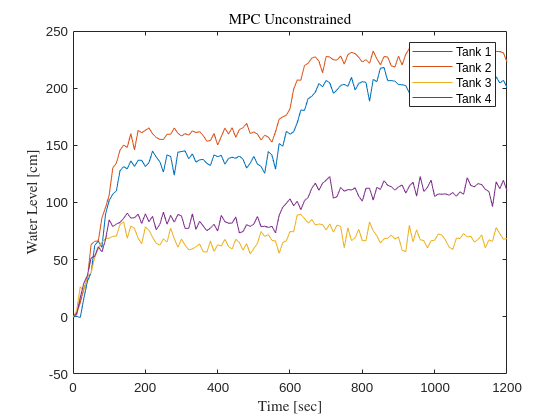


figure()
plot(t,dy+y_ss)
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4')
title('MPC Unconstrained','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

## Problem 9 - MPC with Input Constraints and Soft Output Constraints

% Boundaries
uMin = [   0.0;   0.0 ];      	% [cm^3/s]	:   input lower bound
uMax = [ 500.0; 500.0 ];        % [cm^3/s] 	:   input upper bound
dMin = [   0.0;   0.0 ];        % [cm^3/s]	:   disturbance lower bound
dMax = [ 100.0; 100.0 ];        % [cm^3/s]	:   disturbance lower bound



clear dx dy du
N_pred = 4;
[omega_x, omega_w, gamma] = setupMatrices(ModelDiscrete, N_pred);

y_ss = y(:, end);
x_ss = x(:, end);
u_ss = [0;0];
dy = y-y_ss;
dx = zeros(4,N);
du = zeros(2,N);
dx(:,1) = x(:, 1)-x_ss;
du(:, 1) = u_ss;

ModelDiscrete.r = [90,110,80,80];
r_set_1 = repmat(ModelDiscrete.r(1:2),1,N_step);
r_set_2 = repmat(ModelDiscrete.r(1:2) + [50, 50],1,N);
r_set = [r_set_1, r_set_2];

% u_vec = zeros(2, N);
y_est = zeros(4, N);
w_est = zeros(4, N);
x_est = zeros(4, N);
zeroVec = zeros(N_pred * ModelDiscrete.su, 1);
infVec = inf(N_pred * ModelDiscrete.su, 1);
UMin = repmat(uMin, N_pred, 1);
UMax = repmat(uMax, N_pred, 1);
DMin = repmat(dMin, N_pred, 1);
DMax = repmat(dMax, N_pred, 1);

Aeq = [];
beq = [];
lb = [UMin;zeroVec; zeroVec];
ub = [UMax; infVec; infVec];
x0 = [];

i = 1;
for k = 1:N-1    
    % 1. get deviation variables
    dx(:,k+1) = Ad*dx(:,k)+Bd*du(:, k) + Ed*(w(1:2,k)+dist(:, k));
    dy(:,k+1) = Cd*dx(:,k+1) + v(:,k+1);

    % 2. do the Kalman Filtering 
    e = dy(:,k+1) - Cd*dx(:,k+1);
    
    x_est(:, k) = dx(:,k+1) + kalman.K_fx*e;
    w_est(:, k) = kalman.K_fw * e;
    y_est(:,k) = Cd*x_est(:,k);
    
   
    % 3. get regulation matrices and call qr solver 
    [H_z, g_z] = getObjectiveTermOutput(omega_x, omega_w, gamma, N_pred, r_set(i:i+4*N_pred-1), x_est(:, k), w_est(:, k));
    [H_du, g_du, lambda] = getObjectiveTermDeltaControl(N_pred, ModelDiscrete, (du(:, k)));
    [H_s_l, g_s_l, H_s_u, g_s_u] = getSoftOutputConstraints(N_pred, ModelDiscrete);
    [H_u, g_u] = getObjectiveTermControl(N_pred, ModelDiscrete, u_ss);

    H = H_z + H_du + H_u;   % 8x8 h, lower, upper
    g = g_z + g_du + g_u;  
    
    H_constr = zeros(24, 24);
    H_constr(1:8, 1:8) = H;
    H_constr(9:16, 9:16) = H_s_l;
    H_constr(17:24, 17:24) = H_s_u;

    g_constr = [g; g_s_l; g_s_u];

    A = zeros(24, 24);

   
    % Hessian is not symmetric CORRECTION 
    H = (H+H')/2;

    % check if positive definite
    try chol(H)
        disp('Matrix is symmetric positive definite.')
    catch ME
        disp('Matrix is not symmetric positive definite')
    end

    [u_opt,fval,exitflag,output,lambda] = quadprog(H,g,[],[],[],[],lb,ub,[])
    du(:, k+1) = u_opt(1:2)-u_ss;

    i = i+2;
end

ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   500
   500
   500
   500
   500
   500
   500
   500


fval = -2.6043e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.862645e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.918795e-12, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.8626e-09
    constrviolation: 0
         iterations: 22
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   500
   500
   500
   500
   500
   500
   500
   500


fval = -2.3557e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.862645e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.844790e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.8626e-09
    constrviolation: 0
         iterations: 21
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   500
   500
   500
   500
   500
   500
   500
   500


fval = -2.1059e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.862645e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.763095e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.8626e-09
    constrviolation: 0
         iterations: 21
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.8703e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.793968e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.049091e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 1.210765e-15, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.2404e-05
    constrviolation: 6.0822e-12
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.6409e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 3.725290e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.180349e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 4.547474e-17, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.3807e-06
    constrviolation: 2.2737e-13
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.4185e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.154840e-11,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.458340e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 2.273737e-17, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.8230e-07
    constrviolation: 1.1369e-13
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.2057e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 9.313226e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.541658e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.7943e-05
    constrviolation: 0
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -1.0031e+10

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.196921e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.4894e-06
    constrviolation: 0
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -8.1032e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.998883e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.6101e-06
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -6.2167e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵8.107947e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3320e-05
    constrviolation: 0
         iterations: 17
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000


fval = -4.4625e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 4.656613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.484471e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 9.777068e-16, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 8.7055e-06
    constrviolation: 8.5265e-12
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  500.0000
  500.0000
  500.0000
  500.0000
  402.5016
  500.0000
  252.8139


fval = -2.7929e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.037268e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵7.069351e-17, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.4925e-10
    constrviolation: 0
         iterations: 11
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  500.0000
  449.1829
  434.9621
  185.6569
  362.9324
  217.9808
  405.0120
  256.6576


fval = -1.3493e+09

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.910383e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.070868e-22, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1642e-10
    constrviolation: 0
         iterations: 12
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  167.1589
    0.0000
  325.9532
  159.4250
  370.1061
  225.7024
  412.8846
  263.2345


fval = -5.1553e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.307613e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵4.249284e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 4.4809e-06
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   55.8003
    0.0000
  334.8591
  150.0081
  380.8482
  232.2630
  419.8877
  266.0314


fval = -4.4851e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.112933e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.876348e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 6.4689e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   55.6147
    0.0000
  341.9530
  134.3731
  387.2426
  236.8349
  424.8752
  270.4182


fval = -4.5504e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.173996e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵9.674669e-12, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.4301e-07
    constrviolation: 0
         iterations: 10
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   89.3269
    0.0000
  347.7016
  128.9010
  391.5861
  244.0699
  428.8335
  277.2282


fval = -4.8986e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.165515e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.545434e-11, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.5603e-07
    constrviolation: 0
         iterations: 9
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   96.3580
    0.0000
  352.3695
  130.9253
  395.4978
  250.7443
  432.5857
  283.3953


fval = -5.0802e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.152250e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.048950e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.2721e-08
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   73.8802
    0.0000
  355.9718
  132.1614
  399.1538
  253.7715
  435.9020
  286.1180


fval = -5.0033e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.196011e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.792384e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.8336e-08
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   65.0590
    0.0000
  360.4137
  136.2480
  403.5820
  254.8733
  439.7545
  286.9312


fval = -5.0423e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵1.329262e-22, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1642e-10
    constrviolation: 0
         iterations: 16
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   92.5414
    0.0000
  363.7190
  143.7993
  406.2219
  258.5063
  442.0786
  290.1653


fval = -5.3621e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 5.820757e-15,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵9.124827e-17, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1642e-10
    constrviolation: 0
         iterations: 15
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  103.3020
    0.0000
  365.3580
  151.7019
  407.4861
  262.6614
  443.3723
  293.9411


fval = -5.5410e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵6.256470e-23, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 2.3283e-10
    constrviolation: 0
         iterations: 13
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   98.8258
    0.0000
  368.4493
  168.3235
  410.7047
  265.0769
  446.3050
  295.8436


fval = -5.6667e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.288421e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.491170e-10, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 9.8616e-08
    constrviolation: 0
         iterations: 18
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
  103.6367
    0.0000
  371.5346
  186.4465
  413.8351
  267.2699
  449.0540
  297.5152


fval = -5.8747e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.164153e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.182225e-21, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 1.1642e-10
    constrviolation: 0
         iterations: 12
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


u_opt = 8×1
   76.2921
    0.0000
  374.0249
  196.2688
  416.9348
  265.8458
  451.8847
  295.8753


fval = -5.7541e+08

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 1.039473e-14,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵5.703712e-09, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 7.3491e-05
    constrviolation: 0
         iterations: 8
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [8×1 double]
      upper: [8×1 double]


ans = 8×8
   32.4520    5.7718   23.9742    4.6715   15.8567    3.3228    7.8617    1.7410
         0   34.0412   -0.0197   25.1567   -0.0635   16.6409   -0.0795    8.2584
         0         0   16.5013    0.3558   10.7009    0.3328    5.3629    0.2356
         0         0         0   17.2931   -0.0772   11.2363   -0.0593    5.6279
         0         0         0         0   15.5771    0.2935    7.5551    0.1840
         0         0         0         0         0   16.3257   -0.0836    7.9381
         0         0         0         0         0         0   13.4888    0.2360
         0         0         0         0         0         0         0   14.1388


Matrix is symmetric positive definite.



figure()
plot(t,dy+y_ss)
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4')
title('MPC Constrained','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')


## Problem 10 - Closed-Loop Simulations

`In an ``open``-loop MPC, the control ``input` `is`` used ``as`` a reference ``input` `for`` the system, but it ``is` `not`` applied to the plant model. This means that the plant model ``is` `not`` affected by the control ``input``, ``and`` the control ``input`` does ``not`` influence the plant``'s state.`

clear dx dy du

F = [300, 300, 250, 250];
dist = repmat(F(3:4)', 1, N);
[y, z, x, d, t] = SimulateStochastic(F, 1,"");

kalman = Kalman(Ad, Cd);
y_ss = y(:, end);
x_ss = x(:, end);
u_ss = [0;0];
parameters = GetParameters();
ModelDiscrete = modelDiscrete(Ad, Bd, Cd, Czd, Ed, y_ss)
% setup matrices for optimal control problem 
% they are constant -> offline computation
N_pred = 4;
step_size = 0.01;
[omega_x, omega_w, gamma] = setupMatrices(ModelDiscrete, N_pred);

dy = zeros(4,N);
dx = zeros(4,N);
du = zeros(2,N);
dx(:,1) = x(:, 1)-x_ss;
du(:, 1) = u_ss;

% u_vec = zeros(2, N);
y_est = zeros(4, N);
w_est = zeros(4, N);
x_est = zeros(4, N);
ModelDiscrete.r = [60,60,40,40];    % try out different set points

setpoints = [];

r_set_1 = repmat(ModelDiscrete.r(1:2),1,N_step);
r_set_2 = repmat(ModelDiscrete.r(1:2) + [50, 50],1,N);
r_set = [r_set_1, r_set_2];

i = 1;
for k = 1:N-2  
    setpoints = [setpoints; r_set(i), r_set(i+1)];
    % 1. get deviation variables
    dx(:,k+1) = Ad*dx(:,k)+Bd*du(:, k) + Ed*(w(1:2,k)+d(:, k));
    dy(:,k+1) = Cd*x(:,k) + v(:,k+1);

    % 2. do the Kalman Filtering 
    e = y(:,k) - Cd*dx(:,k+1);
    
    x_est(:, k) = x(:,k) + kalman.K_fx*e;
    w_est(:, k) = kalman.K_fw * e;
    y_est(:,k) = Cd*x_est(:,k);
    
   
    % 3. get regulation matrices and call qr solver 
   [H_z, g_z] = getObjectiveTermOutput(omega_x, omega_w, gamma, N_pred, r_set(i:i+4*N_pred-1), x_est(:, k), w_est(:, k));
   [H_du, g_du] = getObjectiveTermDeltaControl(N_pred, ModelDiscrete, (du(:, k)));
    
    H = H_z + H_du;
    g = (g_z) + g_du;  

    % Hessian is not symmetric CORRECTION 
    H = (H+H')/2;
    disp(k)
    disp(H)
    disp(g)
    [u_opt,fval,exitflag,output,lambda] = quadprog(H,g)
    du(:, k+1) = u_opt(1:2);

    u(:, k) = u_opt(1:2);

    disp(u(:, k))

    % simulate again with new u 
    disturbance_with_noise = d(:,k)+w(:,k);
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[0 4],x(:,k),[],u(:,k),disturbance_with_noise,parameters);
    x(:,k+1) = Xk(end,:)';
    y(:,k+1) = FourTankSystemSensor(x(:,k+1),parameters)+v(:,k+1); % Sensor function

    i = i+2;

end

setpoints = [setpoints; r_set(i), r_set(i+1)];
setpoints = [setpoints; r_set(i), r_set(i+1)];

figure()
plot(t,y(1:2,:))
hold on 
plot(t, dy(1:2,:))
hold on
plot(t, setpoints)
hold off
legend('Tank 1', 'Tank 2', 'Tank 1 Model', 'Tank 2 Model')
title('MPC Unconstrained','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')




clear dx dy du r_set
% setup matrices for optimal con3trol problem 
% they are constant -> offline computation
N_pred = 4;
parameters = GetParameters();
ModelDiscrete.r = [100,95,90,90];

[Lx, Lr, Lu, Ld] = setupUnconstrained(ModelDiscrete,S, Q, N_pred);
setpoint = [];
dx = zeros(4,N);
du = zeros(2,N);
dx(:,1) = x(:, 1);
du(:, 1) = [F(1);F(2)];
 
y_est = zeros(4, N);
w_est = zeros(4, N);
x_est = zeros(4, N);
r_set = repmat(ModelDiscrete.r,N+2*N_step,1);
% setpoints 
for k = 1:length(r_set)
    if k >= N_step
        r_set(k,1) =  r_set(k, 1) + 20;
        r_set(k,2) =  r_set(k, 2) + 15;
    end

end

for k = 1:N-1   
    % 1. get deviation variables
    dx(:,k+1) = Ad*dx(:,k)+Bd*du(:, k) + Ed*(w(1:2,k)+dist(:, k));
    dy(:,k+1) = Cd*dx(:,k+1) + v(:,k+1);

    % 2. do the Kalman Filtering 
    e = dy(:,k+1) - Cd*dx(:,k+1);
    
    x_est(:, k) = dx(:,k+1) + kalman.K_fx*e;
    w_est(:, k) = kalman.K_fw * e;
    y_est(:,k) = Cd*x_est(:,k);
    
   
    % 3. use explicit form to solve for control input 
    u_opt = Lx * x_est(:, k) + Lr * r_set(k:k+2*N_pred-1, 1:2) + Lu * du(:, k) + Ld * w_est(1:2, k);
    du(1, k+1) = u_opt(1,1);
    du(2, k+1) = u_opt(2,1);
    disp(u_opt')

    % simulate again with new u 
    disturbance_with_noise = d(:,k)+w(:,k);
    [Tk,Xk] = ode45(@ModifiedFourTankSystem,[0 4],x(:,k),[],du(:,k+1),disturbance_with_noise,parameters);
    x(:,k+1) = Xk(end,:)';
    y(:,k+1) = FourTankSystemSensor(x(:,k+1),parameters)+v(:,k+1); % Sensor function


end

figure()
plot(t,dy)
hold on 
plot(t, r_set(1:length(t), 1:2))
hold off
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4')
title('MPC Unconstrained','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

figure()
plot(t,dx)
title('MPC Unconstrained','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

## Problem 13 - PID control

Use Simulink 

clear tf
% Setup 
% get parameters
p = GetParameters();

% flow rate steady state
F = [300, 300, 250, 250];

%% get steady state of system 
[xs, hs] = computeSteadyState(p, F)
% get A, B, C, E matrix of system 
[xs, hs] = computeSteadyState(p, F);
[A,B,C,Cz,E] = linearize(p, hs);    % continuous

s = tf('s');
inv_helper = C*inv(eye(4)*s-A);
Gyu = inv_helper*B;
Gyd = inv_helper*E;

% Model
num_11 = Gyd.Numerator{1, 1};
num_13 = Gyd.Numerator{3, 1};
num_22 = Gyd.Numerator{2, 2};
num_24 = Gyd.Numerator{4, 2};

denom_11 = Gyd.Denominator{1, 1};
denom_13 = Gyd.Denominator{3, 1};
denom_22 = Gyd.Denominator{2, 2};
denom_24 = Gyd.Denominator{4, 2};

% P controller
t_step = 1;
r1 = 50;
r2 = 50;
r3 = 40;
r4 = 40;

simOut_P = sim('PController'); 
t_sim = simOut_P.tout;
out1 = simOut_P.out1.signals.values;
out2 = simOut_P.out2.signals.values;
out3 = simOut_P.out3.signals.values;
out4 = simOut_P.out4.signals.values;
% get step response charactaristics
stepinfo(t_sim,out1,r1)

simOut_PI = sim('PIController'); 
t_sim = simOut_PI.tout;
out1 = simOut_PI.ScopeData1.signals.values;
out2 = simOut_PI.ScopeData2.signals.values;
out3 = simOut_PI.ScopeData3.signals.values;
out4 = simOut_PI.ScopeData.signals.values;
% get step response charactaristics
stepinfo(t_sim,out1,r1)


simOut_PID = sim('PIDController'); 
t_sim = simOut_PID.tout;
out1 = simOut_PID.ScopeData1.signals.values;
out2 = simOut_PID.ScopeData2.signals.values;
out3 = simOut_PID.ScopeData3.signals.values;
out4 = simOut_PID.ScopeData.signals.values;
% get step response charactaristics
stepinfo(t_sim,out1,r1)

figure()
plot(t_sim,out1)
hold on 
plot(t_sim, ones(length(t_sim), 1) * r1, 'LineStyle','-')
hold off
legend('Out', 'Setpoint', 'interpreter', 'latex')
title('PID Controller','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

figure()
plot(t_sim,out2)
hold on 
plot(t_sim, ones(length(t_sim), 1) * r2, 'LineStyle','-')
hold off
legend('Out', 'Setpoint', 'interpreter', 'latex')
title('PID Controller','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

figure()
plot(t_sim,out3)
hold on 
plot(t_sim, ones(length(t_sim), 1) * r3, 'LineStyle','-')
hold off
legend('Out', 'Setpoint', 'interpreter', 'latex')
title('PID Controller','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

figure()
plot(t_sim,out4)
hold on 
plot(t_sim, ones(length(t_sim), 1) * r4, 'LineStyle','-')
hold off
legend('Out', 'Setpoint', 'interpreter', 'latex')
title('PID Controller','interpreter','latex')
xlabel('Time [sec]','interpreter','latex')
ylabel('Water Level [cm]','interpreter','latex')

simOut_PI = sim('PIController'); 
t_sim = simOut_PI.tout;
out1 = simOut_PI.ScopeData1.signals.values;
out2 = simOut_PI.ScopeData2.signals.values;
out3 = simOut_PI.ScopeData3.signals.values;
out4 = simOut_PI.ScopeData.signals.values;
% get step response charactaristics
stepinfo(t_sim,out1,r1)

simOut_PID = sim('PIDController'); 
t_sim = simOut_PID.tout;
out1 = simOut_PID.ScopeData1.signals.values;
out2 = simOut_PID.ScopeData2.signals.values;
out3 = simOut_PID.ScopeData3.signals.values;
out4 = simOut_PID.ScopeData.signals.values;
% get step response charactaristics
stepinfo(t_sim,out1,r1)

% simOut_PID = sim('PIDCoupled'); 
% t_sim = simOut_PID.tout;
% out1 = simOut_PID.ScopeData1.signals.values;
% out3 = simOut_PID.ScopeData3.signals.values;
% % get step response charactaristics
% stepinfo(t_sim,out1,r1)
% figure()
% plot(t_sim,out1)
% hold on 
% plot(t_sim, ones(length(t_sim), 1) * r3, 'LineStyle','-')
% hold off
% legend('Out', 'Setpoint', 'interpreter', 'latex')
% title('PID Coupled','interpreter','latex')
% xlabel('Time [sec]','interpreter','latex')
% ylabel('Water Level [cm]','interpreter','latex')
% 
% figure()
% plot(t_sim,out3)
% hold on 
% plot(t_sim, ones(length(t_sim), 1) * r4, 'LineStyle','-')
% hold off
% legend('Out', 'Setpoint', 'interpreter', 'latex')
% title('PID Coupled','interpreter','latex')
% xlabel('Time [sec]','interpreter','latex')
% ylabel('Water Level [cm]','interpreter','latex')

Helper Function

function [z_est, x_est, y_est] = kalmanPrediction(x, dy, du, w, v, F, N, model, kalman)
    dx = zeros(4, N);
    dx(:, 1) = x; 
    for k = 1:N-1
        dx(:,k+1) = model.Ad*dx(:, k)+model.Bd*du + model.Ed*(w+F(3:4)');
        dy(:,k+1) = model.Cd*dx(:, k+1) + v;
    
        e = dy(:,k+1) - model.Cd*dx(:,k+1);
        
        x_est(:, k) = dx(:,k+1) + kalman.K_fx*e;
        y_est(:,k) = model.Cd*x_est(:, k);
        z_est(:, k) = model.Czd * x_est(:, k);
    end

end


function [omega_x, omega_w, gamma, gammaE] = setupMatrices(model, N)
    % N is the number of prediction steps
    % allocate memory
    omega_x = zeros(N*model.sx, model.sx);
    omega_w = zeros(N*model.sx, model.su);
    omega_h = zeros(N*model.sx, model.su);

    H = zeros(N*model.sx, N*model.su);

    omega_x(1:model.sx, :) = model.Cd*model.Ad;
    omega_w(1:model.sx, :) = model.Cd*model.Ed;
    omega_h(1:model.sx, :) = model.Cd*model.Bd;

     
    % rows
    for j = 2:N
        omega_x((j-1)*model.sx+1:j*model.sx, :) = omega_x((j-2)*model.sx+1:(j-1)*model.sx, 1:model.sx)*model.Ad;
        omega_w((j-1)*model.sx+1:j*model.sx, :) = omega_x((j-2)*model.sx+1:(j-1)*model.sx, 1:model.sx)*model.Ed;
        omega_h((j-1)*model.sx+1:j*model.sx, :) = omega_x((j-2)*model.sx+1:(j-1)*model.sx, 1:model.sx)*model.Bd;
    end

    % post processing for H matrix 
    % columns
    % Cd * Bd
    H(:, 1:model.su) = omega_h(:, :);
    Hd(:, 1:model.su) = omega_w(:, :);
    for j = 2:N
        H((j-1)*model.sx+1:N*model.sx, (j-1)*model.su+1:j*model.su) = omega_h(1:(N-j+1)*model.sx,:);
        Hd((j-1)*model.sx+1:N*model.sx, (j-1)*model.su+1:j*model.su) = omega_w(1:(N-j+1)*model.sx,:);
    end

    gamma = H;
    gammaE = Hd;
end


